# Quadratic Live Demo (~3-4 min for compiling)

Welcome to the demo file for the generalized quadratic subdivision algorithm.

The demo will guide you through the key functions, showing their inputs, outputs, and  capabilities. 

This software package is the implementation of the present dissertation:

Alexander Dietz. Ein neuer Ansatz zur Konstruktion von Subdivisionsalgorithmen

Dissertation. Darmstadt: TU Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030194](https://doi.org/10.26083/tuprints-00030194)

and the corresponding English translation:

Alexander Dietz. A New Approach to the Construction of Subdivision Algorithms

TUprints. Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030195](https://doi.org/10.26083/tuprints-00030195)

## Contents

#### 1 Quick Use

#### 2 Background Information, Contact and Licence

#### 3 Properties of the Subdivision Algorithm

#### 4 The Surface Case

#### 4.1 Initial Elements

#### 4.2 Bigger Structures

#### 5 The Volume Case

#### 5.1 Input

#### 5.2 Output: Initial Elements

#### 5.3 Output: Bigger Structures

#### 5.4 Output: Lattice

#### 5.5 Optional Commands

#### 6. Quality-of-Life Functions  

#### 6.1 Plot Function

#### 6.2 Uniform Refinement

## 1 Quick Use

For quick use, there is the function

[S,Lattice] = computeSubdivisionMatrix(Input,Degree,MatrixSize,varargin)

This function automatically selects the appropriate algorithm for creating the subdivision algorithms. The following must be considered:

Input: Must either be a natural number greater than 2 (for the two-dimensional case) or one of the inputs listed below, such as adjacency matrix, edge matrix, or face matrix (for the three-dimensional case).

Degree: Must be 2 (or 'quadratic' or 'Quadratic') for the quadratic case or 3 (or 'cubic' or 'Cubic') for the cubic case.

MatrixSize: Must be 0 (or 'initial' or 'Initial') for initial elements or 1 (or 'big' or 'Big') for larger structures.

If Variant 1 is to be used in the quadratic case, the command must include the optional input

%computeSubdivisionMatrix(Input,Degree,MatrixSize,'mu',value)

with 0 <= value < 1/2.

Also, all optional inputs described below can be used. Examples for the command are:

S=computeSubdivisionMatrix(5,2,0,'mu',1/4);               %2D | quadratic | initial element | V1
S=computeSubdivisionMatrix(6,'quadratic',0);              %2D | quadratic | initial element | V2
S=computeSubdivisionMatrix(3,2,'Big','mu',1/4,'Status');  %2D | quadratic | bigger structure | V1
S=computeSubdivisionMatrix(4,2,1,'PreventInputCheck');    %2D | quadratic | bigger structure | V2
S=computeSubdivisionMatrix(7,3,'initial');                %2D | cubic | initial element 
S=computeSubdivisionMatrix(4,'cubic','big');              %2D | cubic | bigger structure

F=[1,2,3,4,5;...
1,2,7,8,6;...
2,3,7,0,0;...
3,4,8,7,0;...
4,5,6,8,0;...
5,1,6,0,0];

S=computeSubdivisionMatrix(F,2,0,'mu',1/4);                                 %3D | quadratic | initial element | V1
S=computeSubdivisionMatrix(F,"Quadratic",0);                                %3D | quadratic | initial element | V2
[S,Lattice]=computeSubdivisionMatrix(F,2,1,'mu',1/4,'Tolerance',10^(-7));   %3D | quadratic | bigger structure | V1
[S,Lattice]=computeSubdivisionMatrix(F,2,"big",'MaxIterations',50);          %3D | quadratic | bigger structure | V2
[S,Lattice]=computeSubdivisionMatrix(F,3,'Initial');                        %3D | cubic | initial element 
[S,Lattice]=computeSubdivisionMatrix(F,'cubic','big');                      %3D | cubic | bigger structure

## 2 Background Information, Contact and Licence

This demo provides a brief introduction to the algorithm. 

For more details on the code implementation, please refer to the corresponding manual.

For theoretical background, consult the related dissertation:

Alexander Dietz. "Ein neuer Ansatz zur Konstruktion von Subdivisionsalgorithmen"

Dissertation. TU Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030194](https://doi.org/10.26083/tuprints-00030194)

or the corresponding English translation:

Alexander Dietz. "A New Approach to the Construction of Subdivision Algorithms

TUprints. Darmstadt. 2025 DOI: [https://doi.org/10.26083/tuprints-00030195](https://doi.org/10.26083/tuprints-00030195)

The code may be used under the

CC-BY 4.0 International

license by citing the corresponding dissertation and its English translation.

For comments, questions, or to report any errors, you can contact us at any time at:

alexander_dietz@t-online.de

## 3 Properties of the Subdivision Algorithm and Variants

For the quadratic case, two variants of the algorithm are available. Files for the first variant end with "V1", and files for the second variant end with "V2".

Both variants share a dominant eigenvalue of 1. The subdominant eigenvalue is 1/2 – double for the surface case and triple for the volume case. Both variants can be applied to any combinatorial structure.

The first variant has the advantage that the subsubdominant eigenvalue is 1/4.

The second variant avoids negative entries and naturally handles semi-irregular volumetric cases through the construction of the subdivision matrix.

## 4 The Surface Case

Let's start with the surface case. This case is relatively simple, as both the theory and practical applications are well established. There are four main files for this case:

computeBiQuadraticSubdivisionMatrixV1(n)

computeBiQuadraticSubdivisionMatrixV2(n)

computeBiQuadraticSubdivisionMatrixV1Big(n)

computeBiQuadraticSubdivisionMatrixV2Big(n)

Functions without the suffix "Big" compute subdivision  matrices for initial elements, refining an n-sided polytope into a smaller one.

Functions with the suffix "Big" compute subdivision matrices for a larger area to enable B-spline evaluations, refining a ring into a smaller ring of B-spline patches. 

Input: n is a natural number > 2,  indicating the number of vertices around the central 2-polytope. 

Output: the corresponding subdivision matrix. 

### 4.1 Initial Elements

Let's look at an example with n=5. Using the following command we obtain the subdivision matrix:

S1=computeBiQuadraticSubdivisionMatrixV1(5)

S1 =     0.5000    0.1809    0.0691    0.0691    0.1809
    0.1809    0.5000    0.1809    0.0691    0.0691
    0.0691    0.1809    0.5000    0.1809    0.0691
    0.0691    0.0691    0.1809    0.5000    0.1809
    0.1809    0.0691    0.0691    0.1809    0.5000


The eigenvalues of this matrix are:

sort(eig(S1),'descend')

ans =     1.0000
    0.5000
    0.5000
    0.2500
    0.2500


The subdominant eigenvectors can be plotted as follows: 

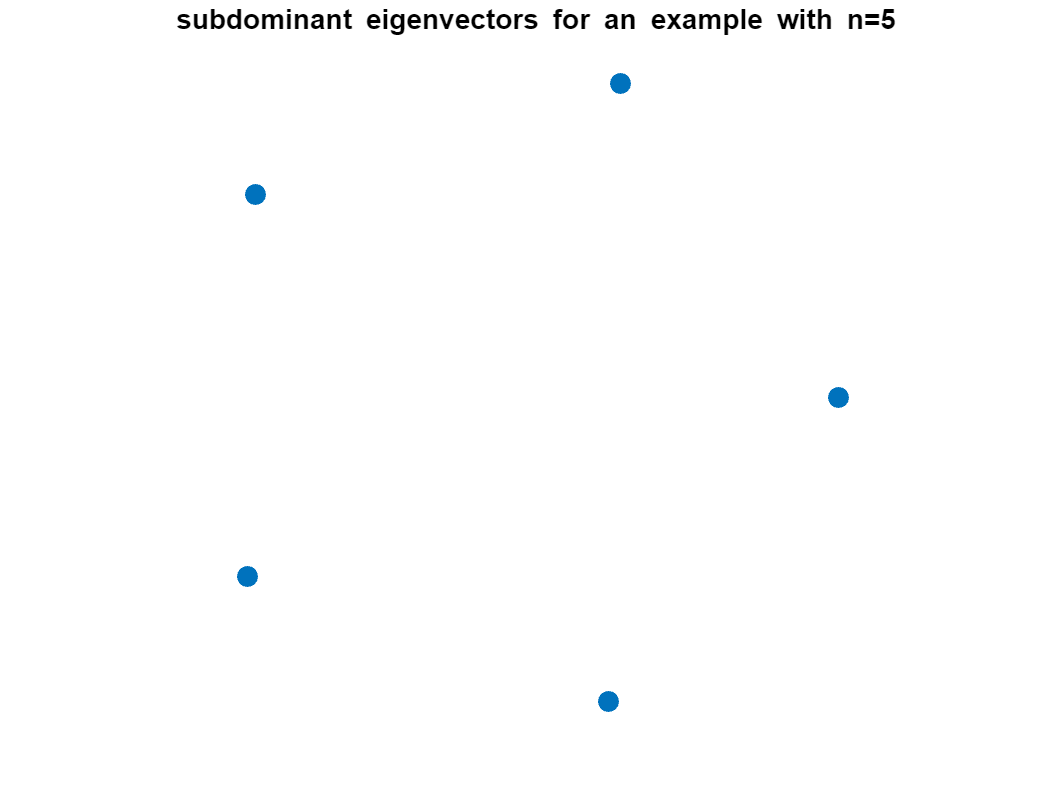

B=S1-1/2*eye(length(S1));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for an example with n=5 \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

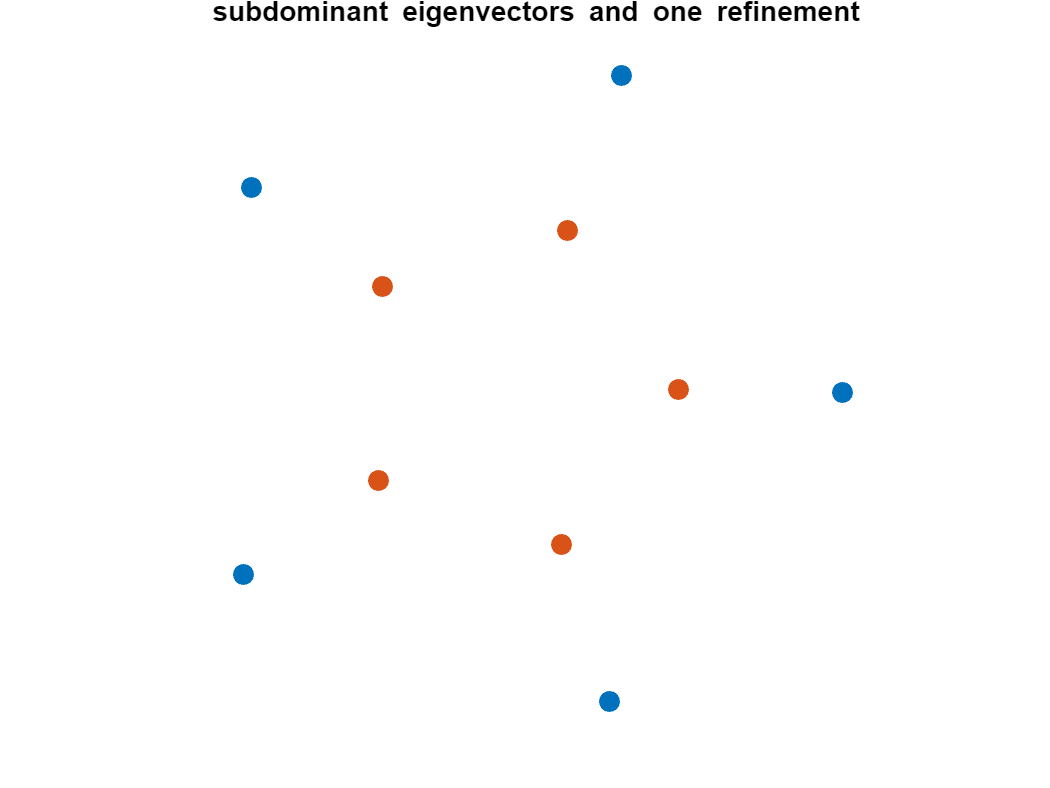

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinement \newline  ')

V=S1*V;
plot(V(:,1),V(:,2),'.r','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

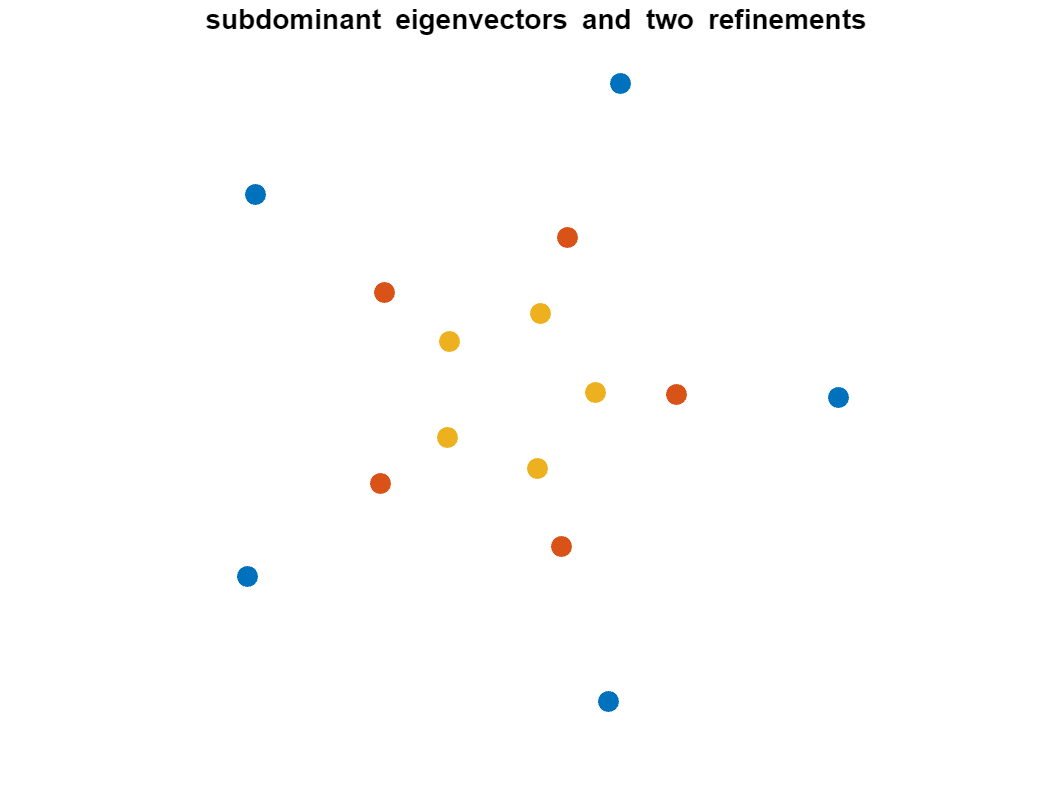

B=S1-1/2*eye(length(S1));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=S1*V;
plot(V(:,1),V(:,2),'.r','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S1*V;
plot(V(:,1),V(:,2),'.r','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

Similar results are obtained for the second variant. Using the following command we obtain the subdivision matrix:

S2=computeBiQuadraticSubdivisionMatrixV2(5)

S2 =     0.4652    0.2091    0.0583    0.0583    0.2091
    0.2091    0.4652    0.2091    0.0583    0.0583
    0.0583    0.2091    0.4652    0.2091    0.0583
    0.0583    0.0583    0.2091    0.4652    0.2091
    0.2091    0.0583    0.0583    0.2091    0.4652


The eigenvalues of this matrix are:

sort(eig(S2),'descend')

ans =     1.0000
    0.5000
    0.5000
    0.1629
    0.1629


The subdominant eigenvectors can be plotted as follows: 

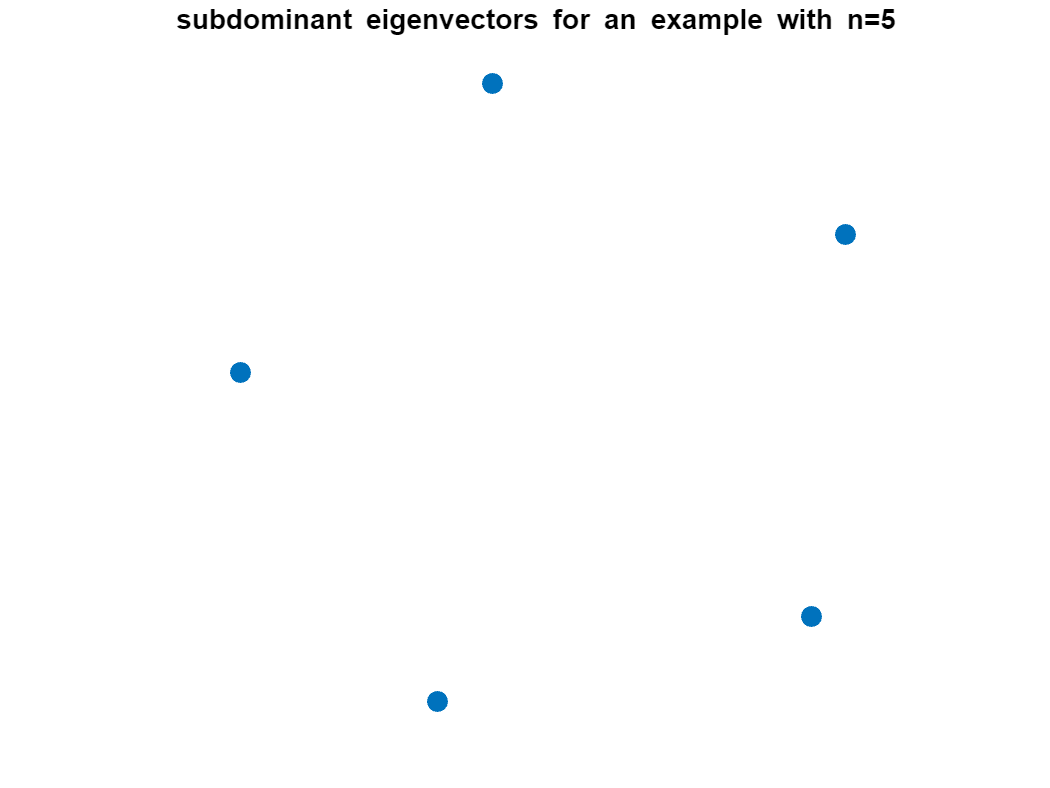

B=S2-1/2*eye(length(S2));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for an example with n=5 \newline  ')

Multiplying the subdivision matrix by the eigenvector results in: 

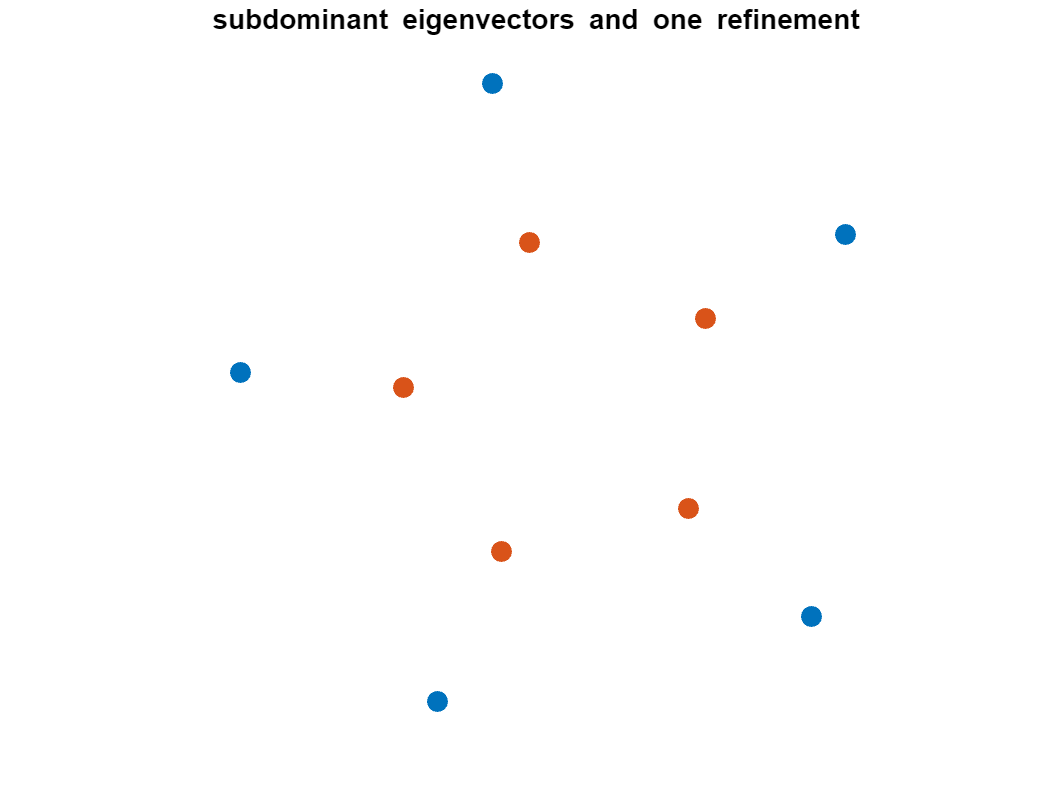

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinement \newline  ')

V=S2*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

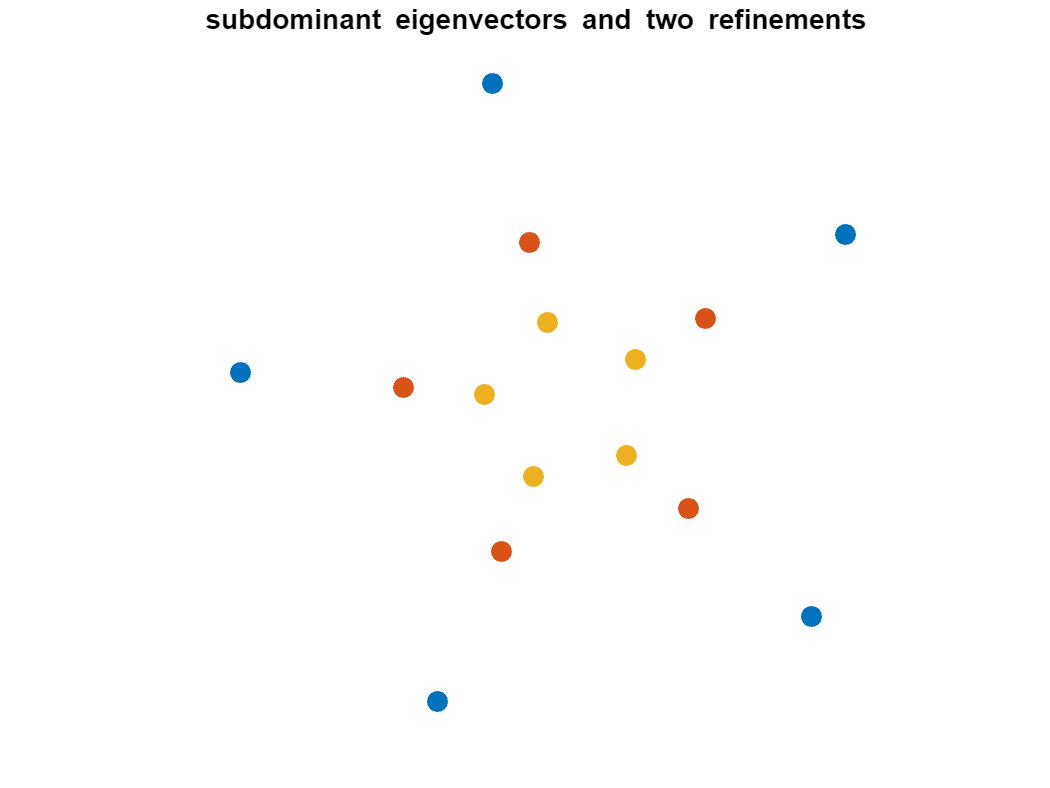

B=S2-1/2*eye(length(S2));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=S2*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S2*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

### 4.2 Bigger Structures

Larger matrices can be computed similarly. Using the following command we obtain the subdivision matrix. Its structure is:

S1Big=computeBiQuadraticSubdivisionMatrixV1Big(5)

S1Big =          0         0         0         0    0.5625    0.1875         0    0.1875    0.0625         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1875    0.5625         0    0.0625    0.1875         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.5625         0         0    0.1875

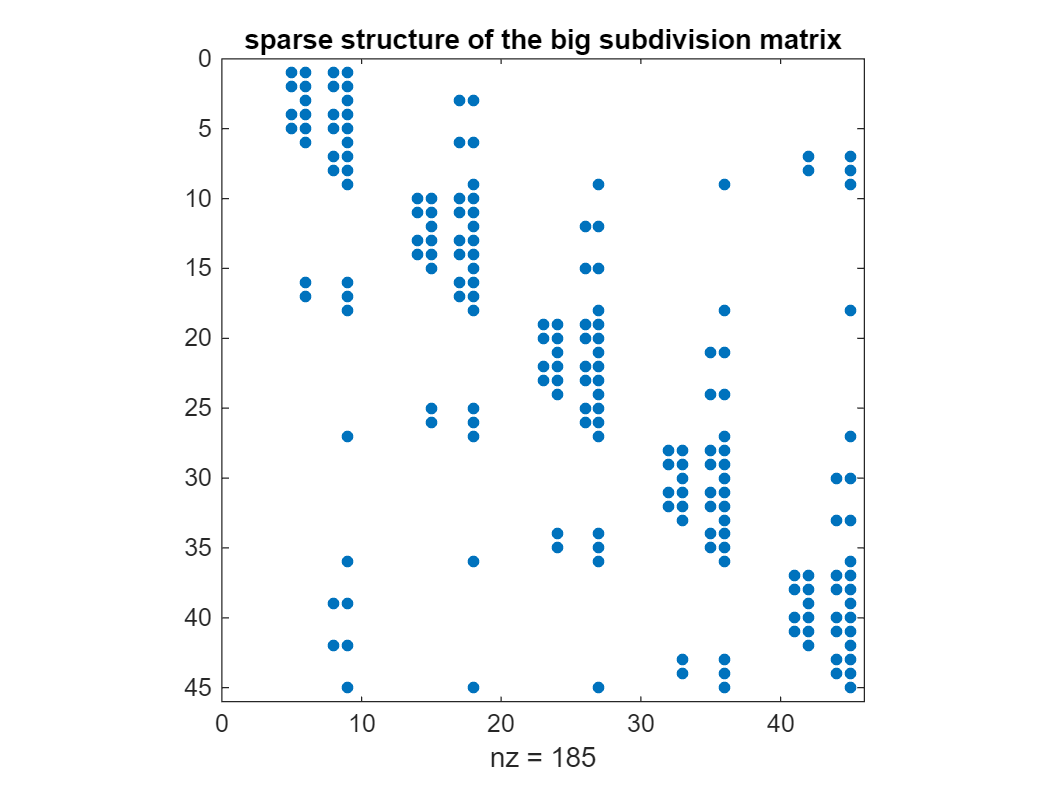

figure
spy(S1Big);
hold on
title('sparse structure of the big subdivision matrix')

The eigenvalues are: 

sort(eig(S1Big),'descend')

ans =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 - 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i


The subdominant eigenvectors can be plotted as follows: 

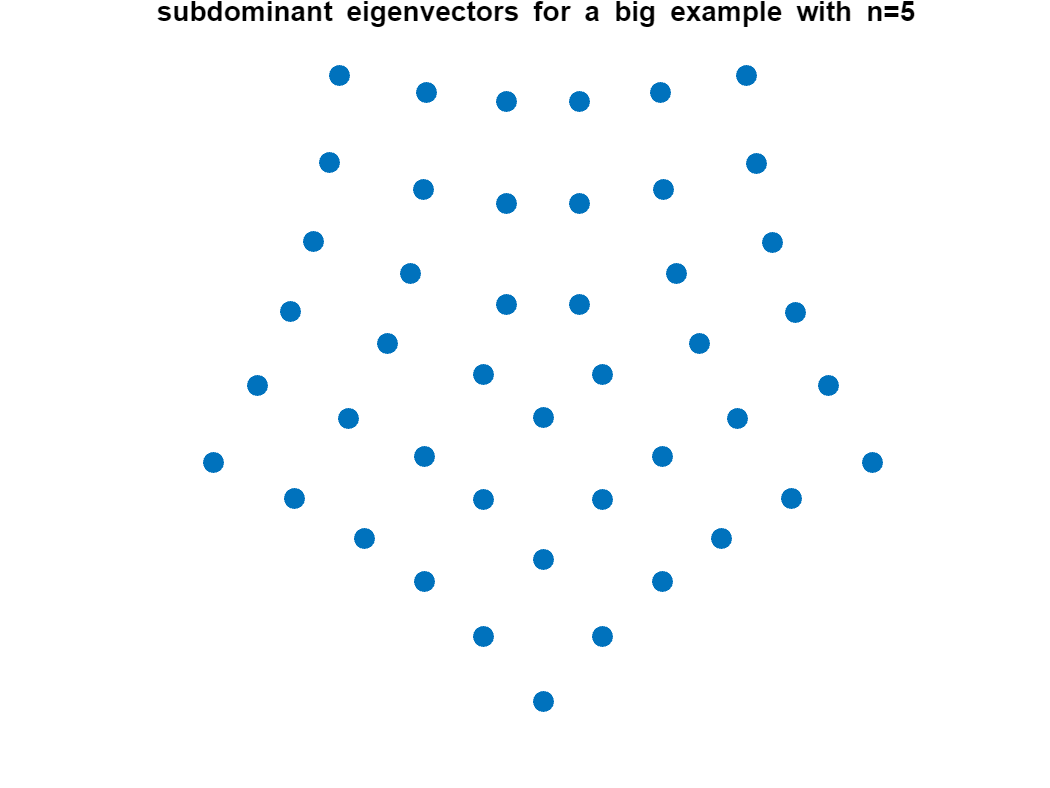

B=S1Big-1/2*eye(length(S1Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for a big example with n=5 \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

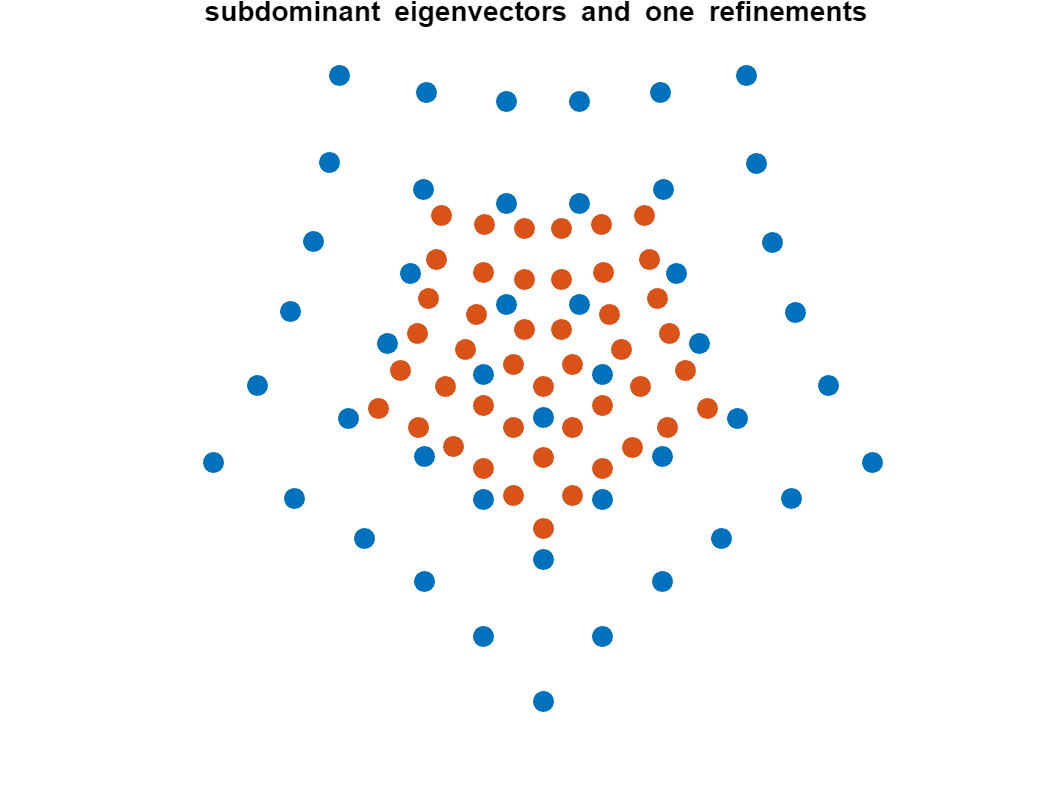

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinements \newline  ')

V=S1Big*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

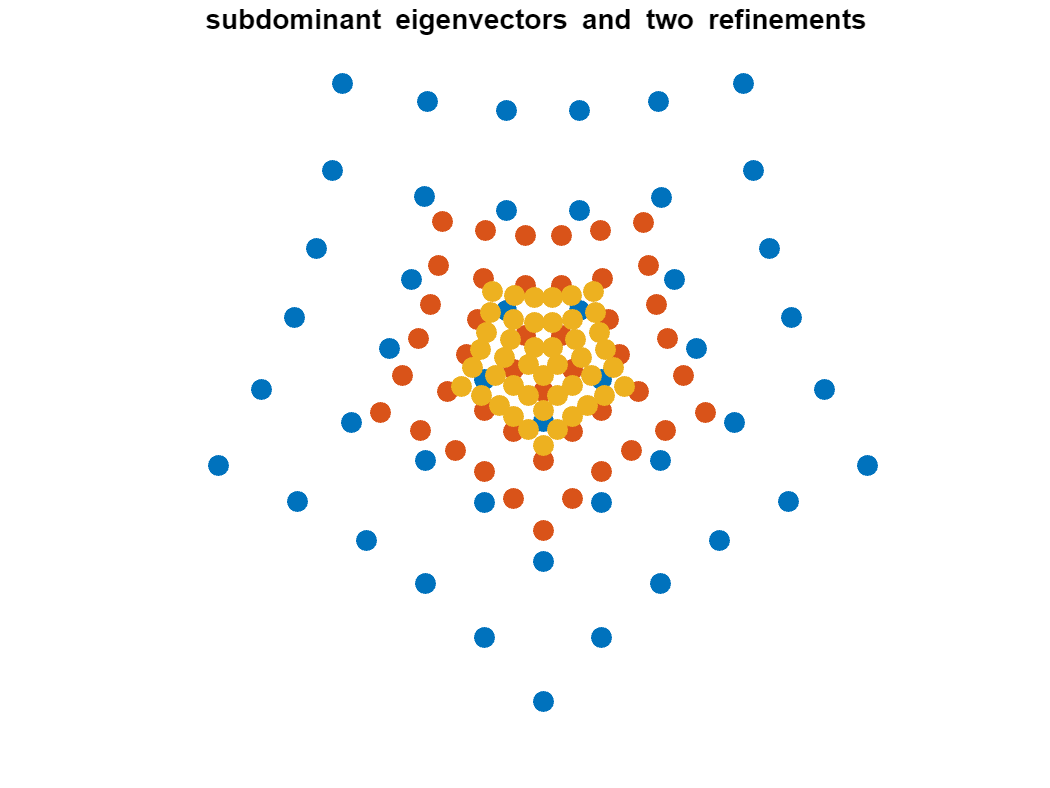

B=S1Big-1/2*eye(length(S1Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=S1Big*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S1Big*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

Similarly, using the following command we obtain the subdivision matrix for variant 2. Its structure is:

S2Big=computeBiQuadraticSubdivisionMatrixV2Big(5)

S2Big =          0         0         0         0    0.5625    0.1875         0    0.1875    0.0625         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1875    0.5625         0    0.0625    0.1875         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.5625         0         0    0.1875

figure
spy(S2Big);
title('sparse structure of the big subdivision matrix')

The six largest eigenvalues are: 

sort(eig(S2Big),'descend')

ans =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.1629 + 0.0000i
   0.1629 + 0.0000i


The subdominant eigenvectors can be plotted as follows: 

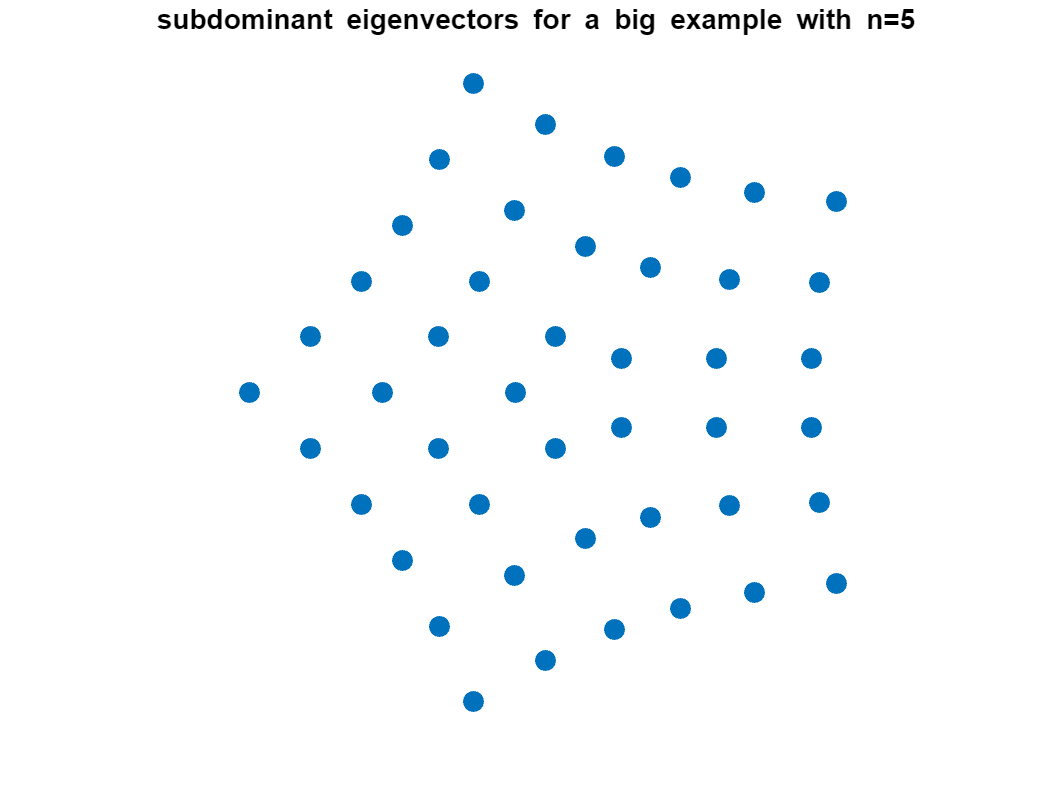

B=S2Big-1/2*eye(length(S2Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for a big example with n=5 \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

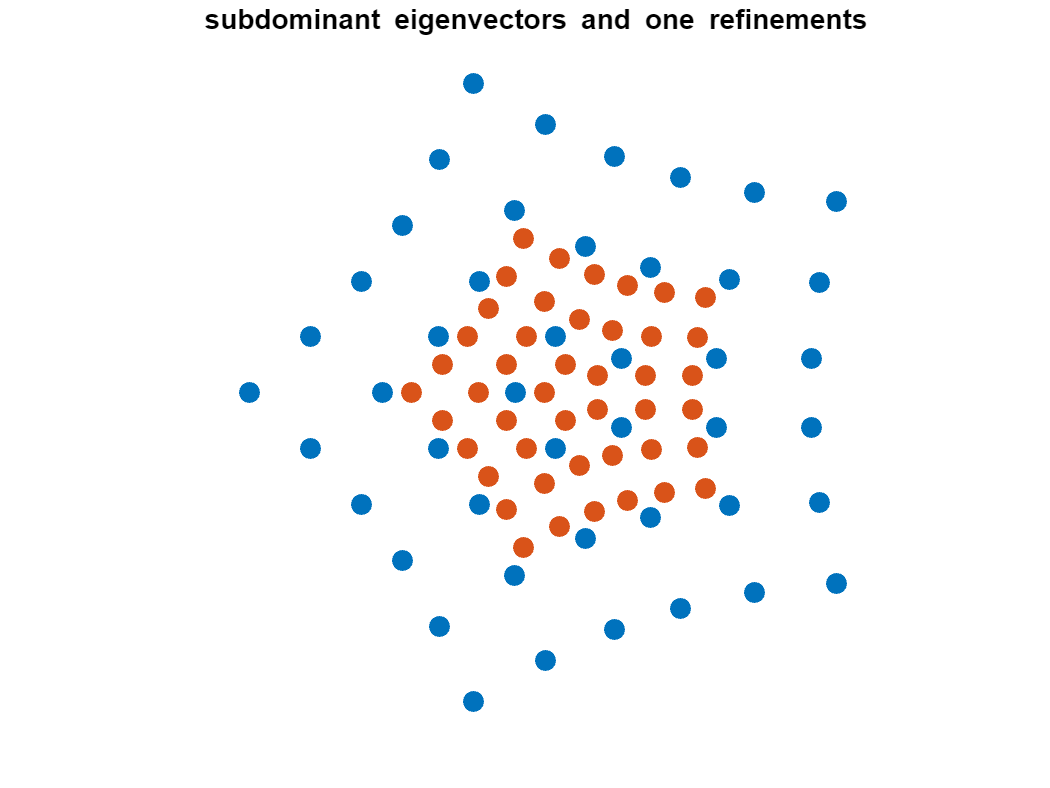

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinements \newline  ')

V=S2Big*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

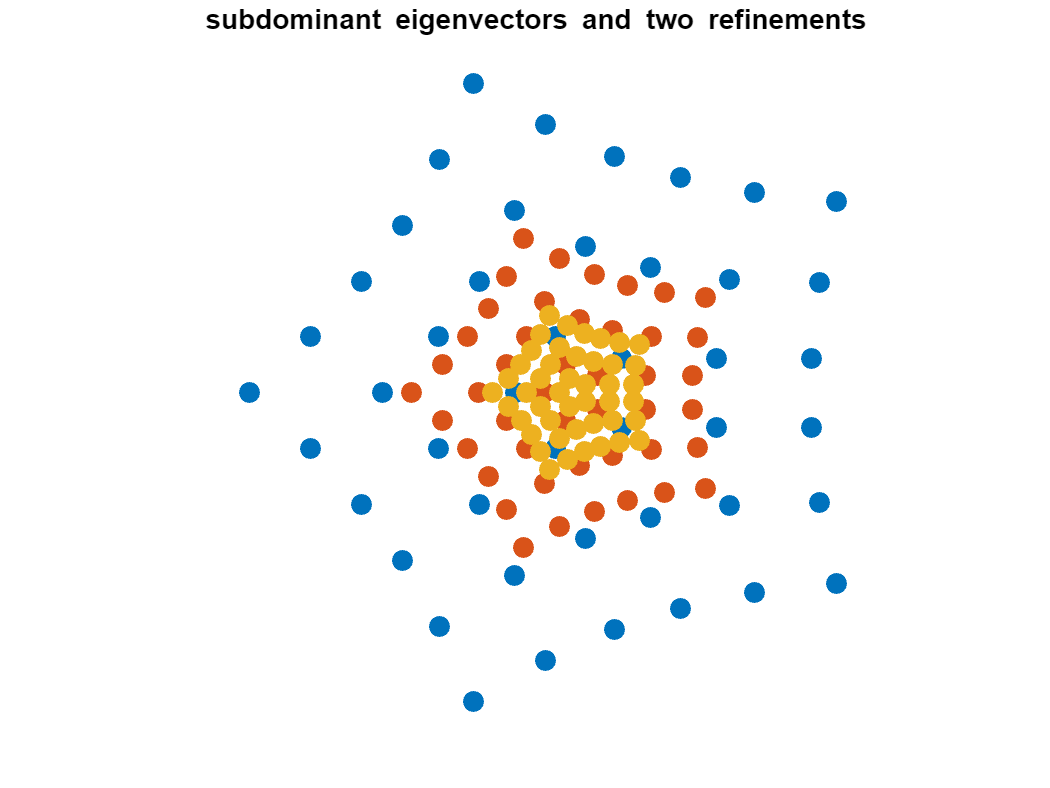

B=S2Big-1/2*eye(length(S2Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=S2Big*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S2Big*V;
plot(V(:,1),V(:,2),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

## 5 The Volume Case

We will now begin with the volume case. There are again 4 main files for this volume case:

computeTriQuadraticSubdivisionMatrixV1(Input,mu,varargin)

computeTriQuadraticSubdivisionMatrixV2(Input,varargin)

computeTriQuadraticSubdivisionMatrixV1Big(Input,mu,varargin)

computeTriQuadraticSubdivisionMatrixV2Big(Input,varargin)

The functions without the "Big" suffix compute subdivision matrices for the initial stages of subdivision. These refine a 3-polytope into a smaller one. 

The functions with the "Big" suffix compute subdivision matrices for a larger area to support B-spline evaluation. Specifically, these functions refine a shell into a smaller shell of B-spline cubes. 

### 5.1 Input

We will now look at the general input, which is the parameter "Input". For all four functions, this input represents the combinatorial structure of the central polytope.

There are three possible data formats. The first is the adjacency matrix. For the regular case, an example would be: 

A=computePrismFaceMatrix(4);
A=FaceToAdjacencyMatrix(A)

A =      0     1     0     1     1     0     0     0
     1     0     1     0     0     1     0     0
     0     1     0     1     0     0     1     0
     1     0     1     0     0     0     0     1
     1     0     0     0     0     1     0     1
     0     1     0     0     1     0     1     0
     0     0     1     0     0     1     0     1
     0     0     0     1     1     0     1     0


Alternatively, the input can be a list of faces. Each row of this list matrix represents a face, and each entry is a vertex of that face. For the regular case, an example would be:

F=computeFaceMatrix(A,false)

F =      1     2     3     4
     1     2     6     5
     1     4     8     5
     2     3     7     6
     3     4     8     7
     5     6     7     8


The third option is a list of edges. For the regular case, this would look like: 

G=graph(A);
E=G.Edges.EndNodes

E =      1     2
     1     4
     1     5
     2     3
     2     6
     3     4
     3     7
     4     8
     5     6
     5     8


For the V1 variant, there is an additional input called "mu". This parameter determines the subsubdominant eigenvalue for the central structure and can be chosen by the user. 

mu=1/4

mu = 0.2500

### 5.2 Output: Initial Elements

Before we look at the optional input parameters, let''s review the output. For the functions without the "Big" suffix, the output is simply the subdivision matrix, which refines a 3-polytope into a smaller one. For the regular case, we obtain 

A=computePrismFaceMatrix(4)

A =      1     2     3     4
     5     6     7     8
     1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8


and using the following command we get

S=computeTriQuadraticSubdivisionMatrixV1(A,1/4)

S =     0.4219    0.1406    0.0469    0.1406    0.1406    0.0469    0.0156    0.0469
    0.1406    0.4219    0.1406    0.0469    0.0469    0.1406    0.0469    0.0156
    0.0469    0.1406    0.4219    0.1406    0.0156    0.0469    0.1406    0.0469
    0.1406    0.0469    0.1406    0.4219    0.0469    0.0156    0.0469    0.1406
    0.1406    0.0469    0.0156    0.0469    0.4219    0.1406    0.0469    0.1406
    0.0469    0.1406    0.0469    0.0156    0.1406    0.4219    0.1406    0.0469
    0.0156    0.0469    0.1406    0.0469    0.0469    0.1406    0.4219    0.1406
    0.0469    0.0156    0.0469    0.1406    0.1406    0.0469    0.1406    0.4219


Similarly, for the second variant, using the following command we get: 

S=computeTriQuadraticSubdivisionMatrixV2(A)

S =     0.4219    0.1406    0.0469    0.1406    0.1406    0.0469    0.0156    0.0469
    0.1406    0.4219    0.1406    0.0469    0.0469    0.1406    0.0469    0.0156
    0.0469    0.1406    0.4219    0.1406    0.0156    0.0469    0.1406    0.0469
    0.1406    0.0469    0.1406    0.4219    0.0469    0.0156    0.0469    0.1406
    0.1406    0.0469    0.0156    0.0469    0.4219    0.1406    0.0469    0.1406
    0.0469    0.1406    0.0469    0.0156    0.1406    0.4219    0.1406    0.0469
    0.0156    0.0469    0.1406    0.0469    0.0469    0.1406    0.4219    0.1406
    0.0469    0.0156    0.0469    0.1406    0.1406    0.0469    0.1406    0.4219


Next, we will illustrate the algorithms with a more complex example. From now on, we will use the face matrix as input.

F=[1,2,3,4,5;...
1,2,7,8,6;...
2,3,7,0,0;...
3,4,8,7,0;...
4,5,6,8,0;...
5,1,6,0,0]

F =      1     2     3     4     5
     1     2     7     8     6
     2     3     7     0     0
     3     4     8     7     0
     4     5     6     8     0
     5     1     6     0     0


For the first variant, using the following command we obtain the subdivision matrix: 

S1=computeTriQuadraticSubdivisionMatrixV1(F,1/4)

S1 =     0.4333    0.1345    0.0573    0.0313    0.1274    0.1274    0.0573    0.0313
    0.1345    0.4333    0.1274    0.0313    0.0573    0.0573    0.1274    0.0313
    0.0573    0.1274    0.4161    0.1373    0.0655    0.0215    0.1221    0.0528
    0.0313    0.0313    0.1373    0.4845    0.1373    0.0528    0.0528    0.0726
    0.1274    0.0573    0.0655    0.1373    0.4161    0.1221    0.0215    0.0528
    0.1274    0.0573    0.0215    0.0528    0.1221    0.4161    0.0655    0.1373
    0.0573    0.1274    0.1221    0.0528    0.0215    0.0655    0.4161    0.1373
    0.0313    0.0313    0.0528    0.0726    0.0528    0.1373    0.1373    0.4845


The eigenvalues of this matrix are: 

D=sort(eig(S1),'descend')

D =     1.0000
    0.5000
    0.5000
    0.5000
    0.2500
    0.2500
    0.2500
    0.2500


The subdominant eigenvectors can be plotted as follows: 

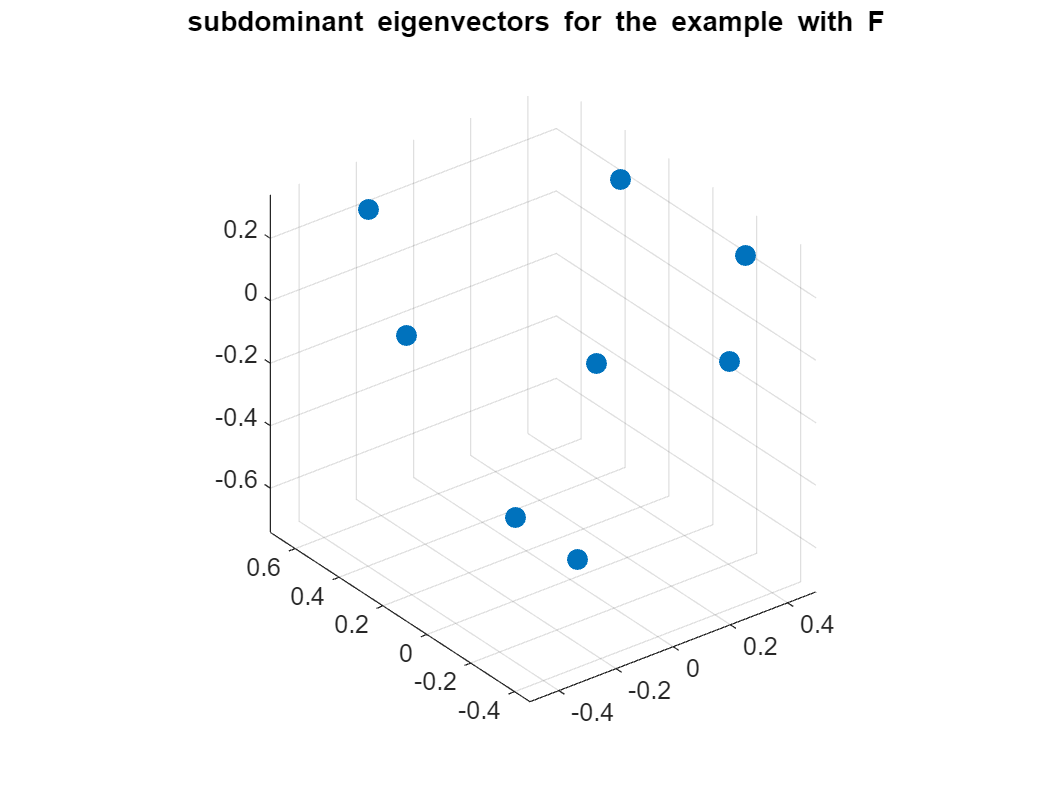

B=S1-1/2*eye(length(S1));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors for the example with F \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

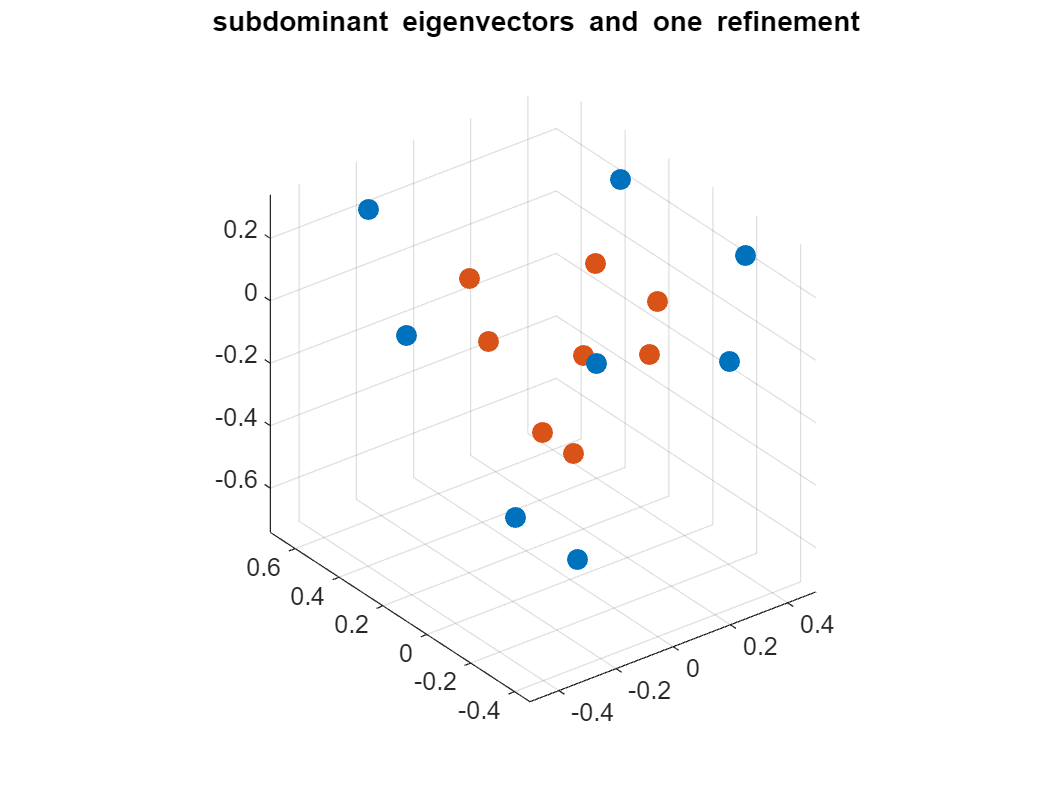

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors and one refinement \newline  ')

V=S1*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

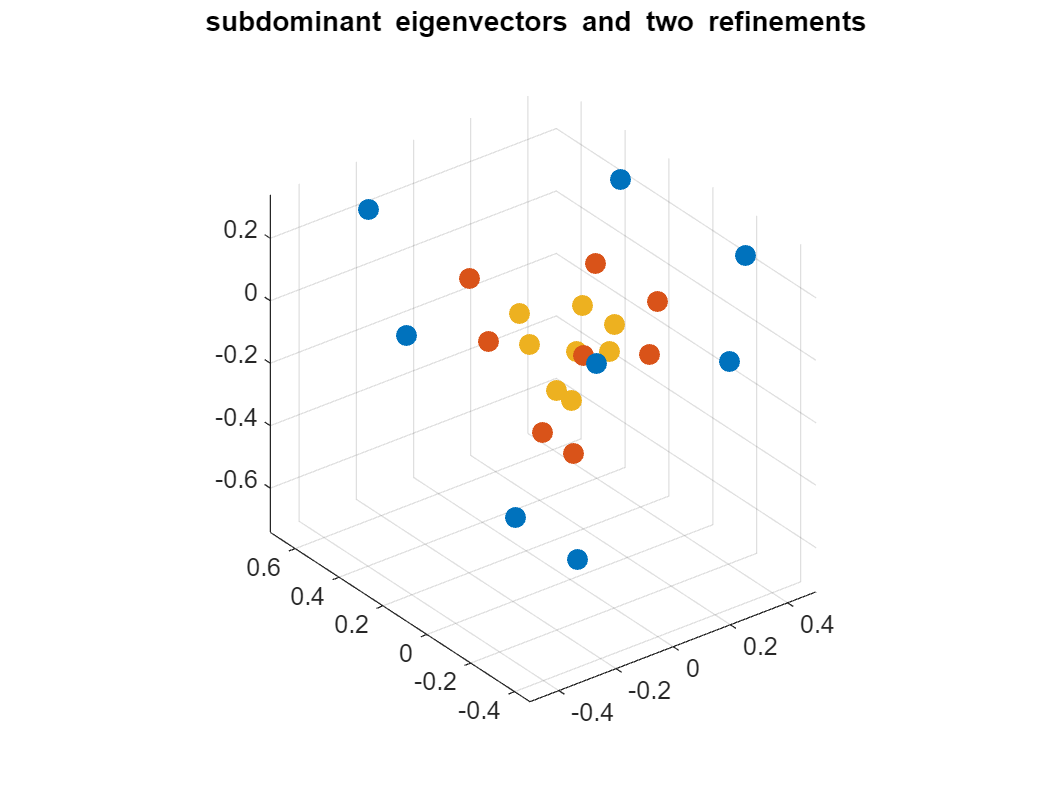

B=S1-1/2*eye(length(S1));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors and two refinements \newline  ')

V=S1*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S1*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

For the second variant, using the following command we obtain the subdivision matrix: 

S2=computeTriQuadraticSubdivisionMatrixV2(F)

S2 =     0.4162    0.1814    0.0334    0.0419    0.1258    0.1258    0.0334    0.0419
    0.1814    0.4162    0.1258    0.0419    0.0334    0.0334    0.1258    0.0419
    0.0523    0.1969    0.3261    0.1965    0.0369    0.0143    0.1244    0.0526
    0.0444    0.0444    0.1329    0.4864    0.1329    0.0356    0.0356    0.0879
    0.1969    0.0523    0.0369    0.1965    0.3261    0.1244    0.0143    0.0526
    0.1969    0.0523    0.0143    0.0526    0.1244    0.3261    0.0369    0.1965
    0.0523    0.1969    0.1244    0.0526    0.0143    0.0369    0.3261    0.1965
    0.0444    0.0444    0.0356    0.0879    0.0356    0.1329    0.1329    0.4864


The eigenvalues of this matrix are: 

D=sort(eig(S2),'descend')

D =     1.0000
    0.5000
    0.5000
    0.5000
    0.1791
    0.1736
    0.1341
    0.1227


The subdominant eigenvectors can be plotted as follows: 

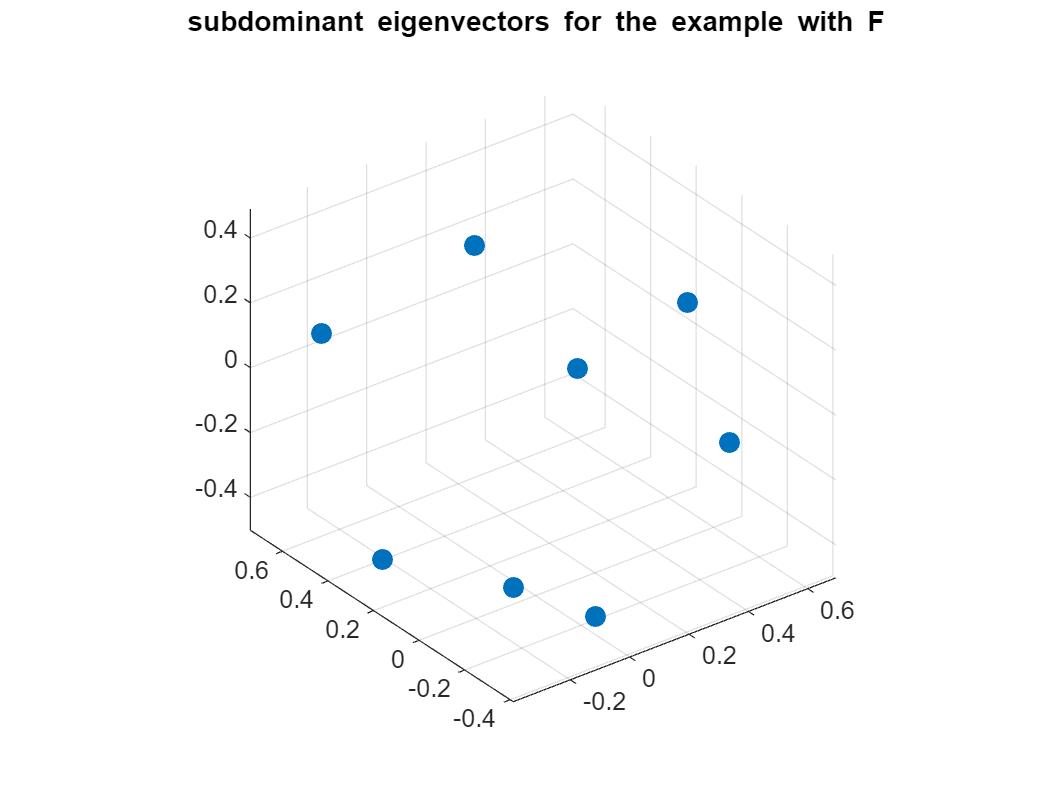

B=S2-1/2*eye(length(S2));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors for the example with F \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

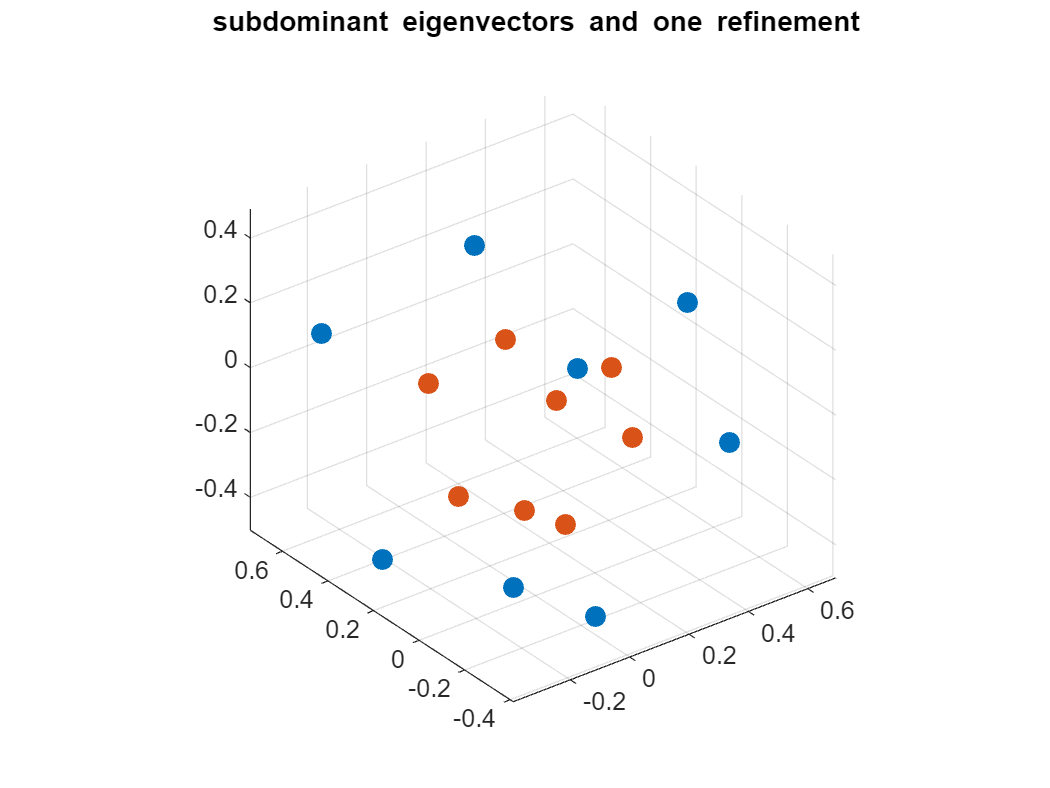

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors and one refinement \newline  ')

V=S2*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

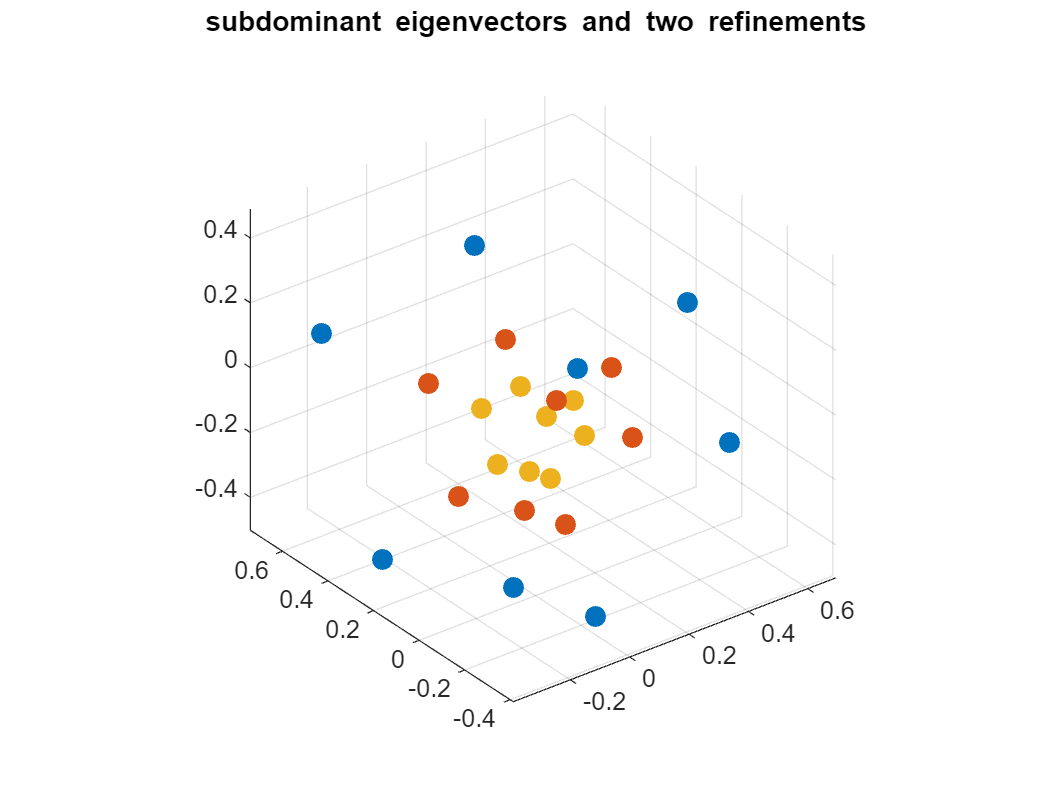

B=S2-1/2*eye(length(S2));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
grid on
title('subdominant eigenvectors and two refinements \newline  ')

V=S2*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S2*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

### 5.3 Output: Bigger Structures

The larger matrices are quite similar. Using the following command we obtain the subdivision matrix with the structure: 

F=[1,2,3,4,5;...
1,2,7,8,6;...
2,3,7,0,0;...
3,4,8,7,0;...
4,5,6,8,0;...
5,1,6,0,0];

S1Big=computeTriQuadraticSubdivisionMatrixV1Big(F,1/4)

S1Big =     0.4333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1345         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.1667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

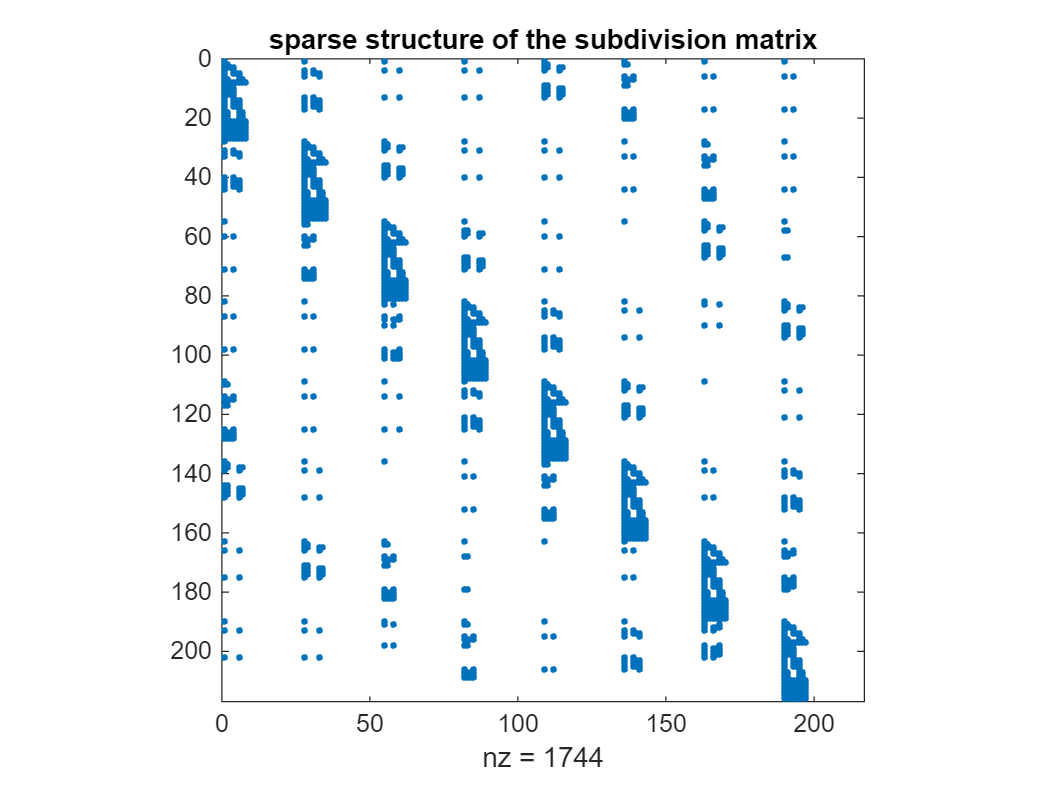

figure
spy(S1Big);
hold on
title('sparse structure of the subdivision matrix')

The eigenvalues of this matrix are: 

sort(eig(S1Big),'descend')

ans =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 - 0.0000i
   0.5000 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 - 0.0000i
   0.2500 + 0.0000i
   0.2500 - 0.0000i


The subdominant eigenvectors can be plotted as follows: 

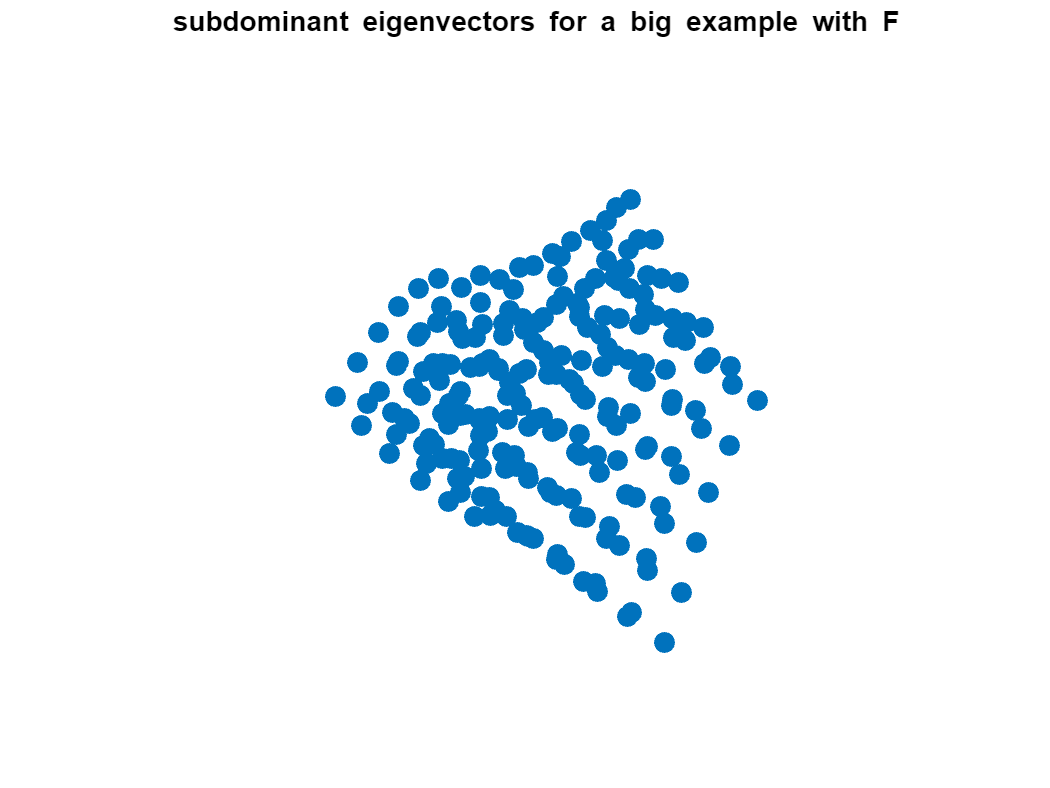

B=S1Big-1/2*eye(length(S1Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for a big example with F \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

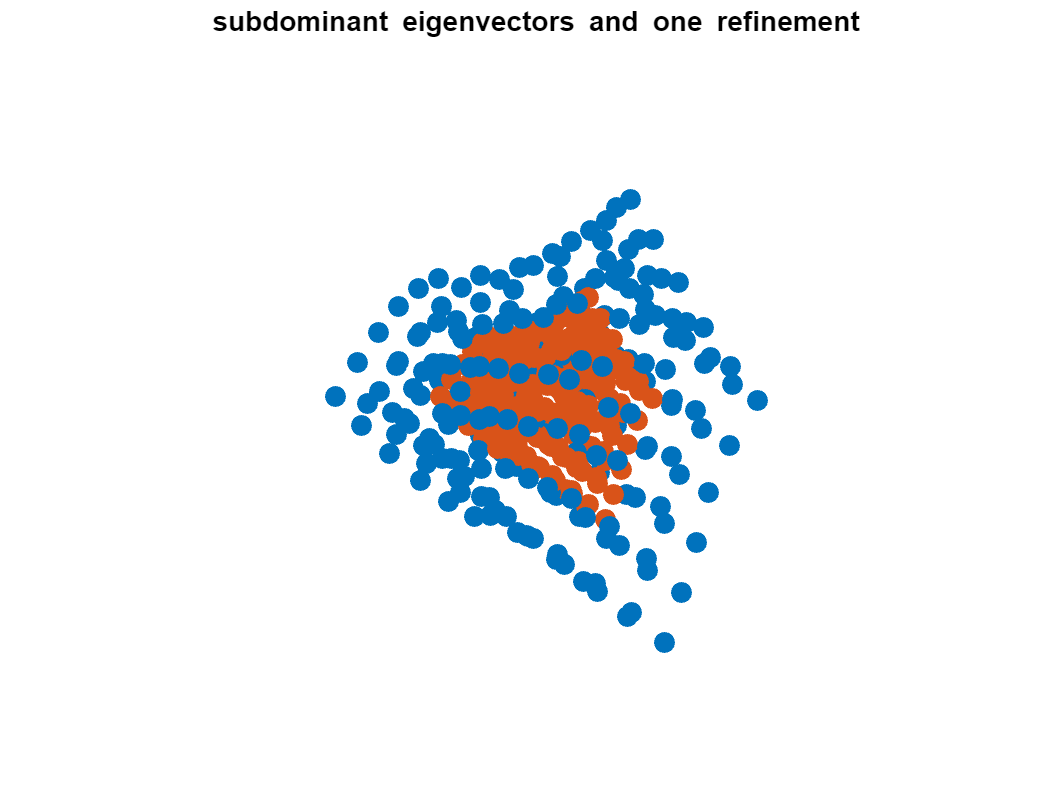

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinement \newline  ')

V=S1Big*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

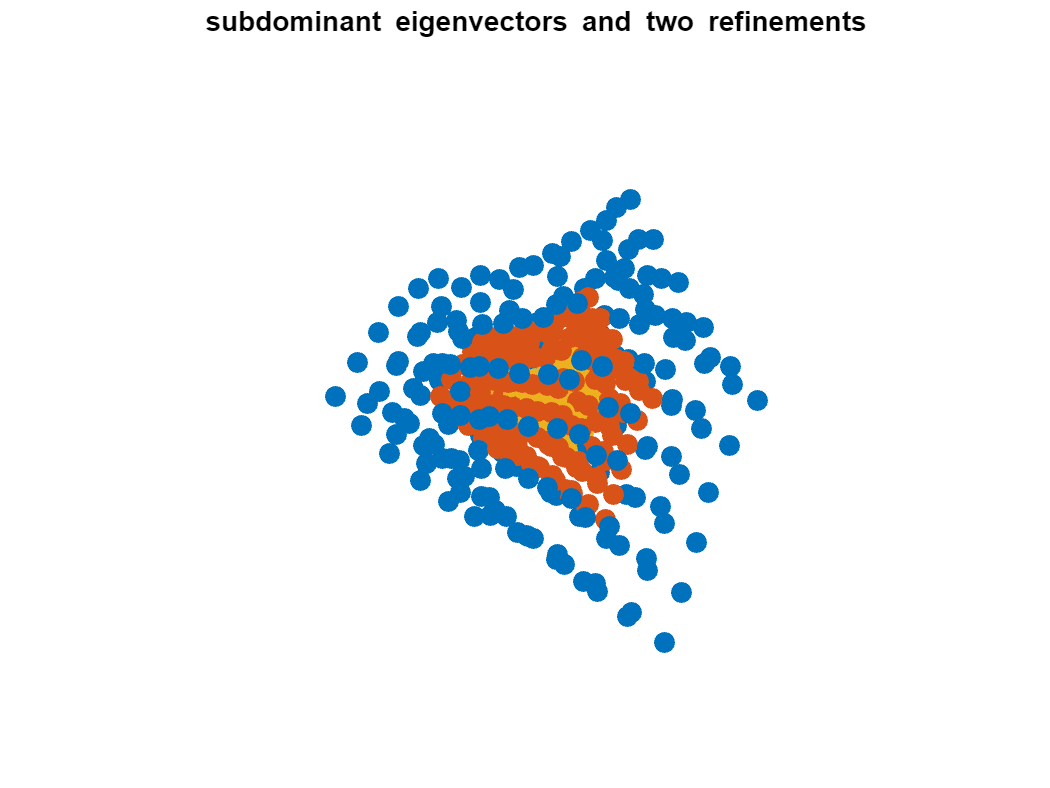

B=S1Big-1/2*eye(length(S1Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=S1Big*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S1Big*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

Using the following command we obtain the subdivision matrix for variant 2. The structure of the matrix is: 

S2Big=computeTriQuadraticSubdivisionMatrixV2Big(F)

S2Big =     0.4162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1814         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.1667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

figure
spy(S2Big);
title('sparse structure of the subdivision matrix')

The eigenvalues of this matrix are: 

sort(eig(S2Big),'descend')

ans =    1.0000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.5000 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i
   0.2500 + 0.0000i


The subdominant eigenvectors can be plotted as follows: 

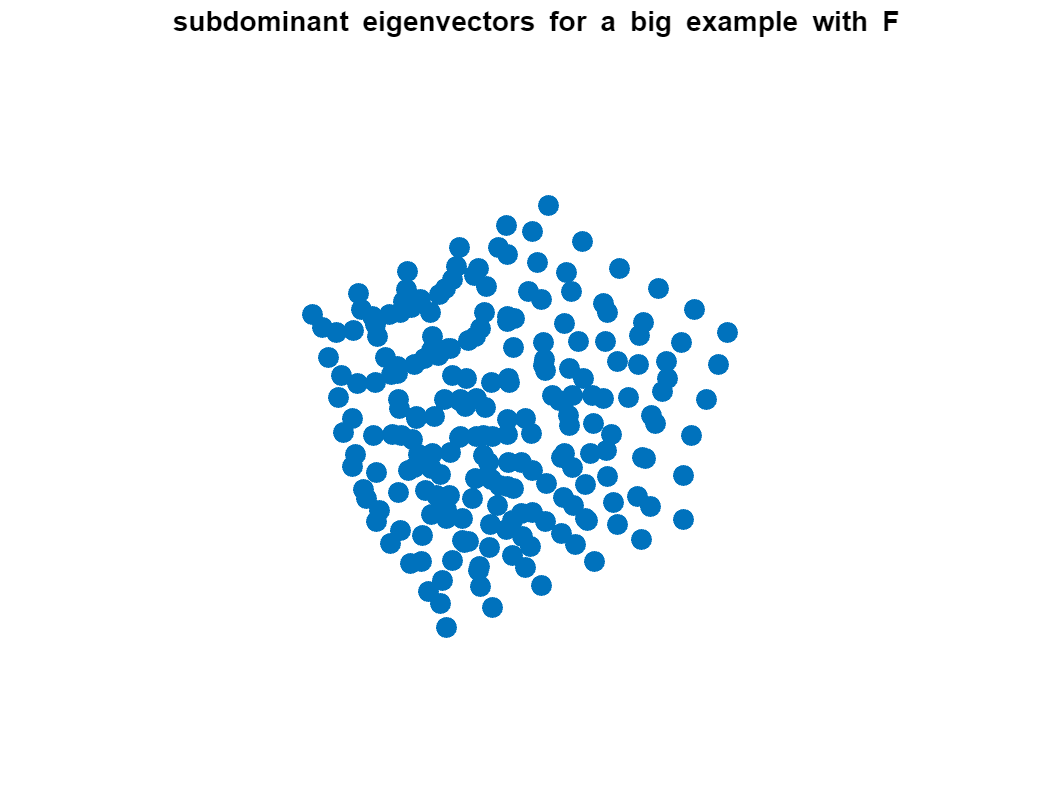

B=S2Big-1/2*eye(length(S2Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors for a big example with F \newline  ')

Multiplying the subdivision matrix by the eigenvectors results in: 

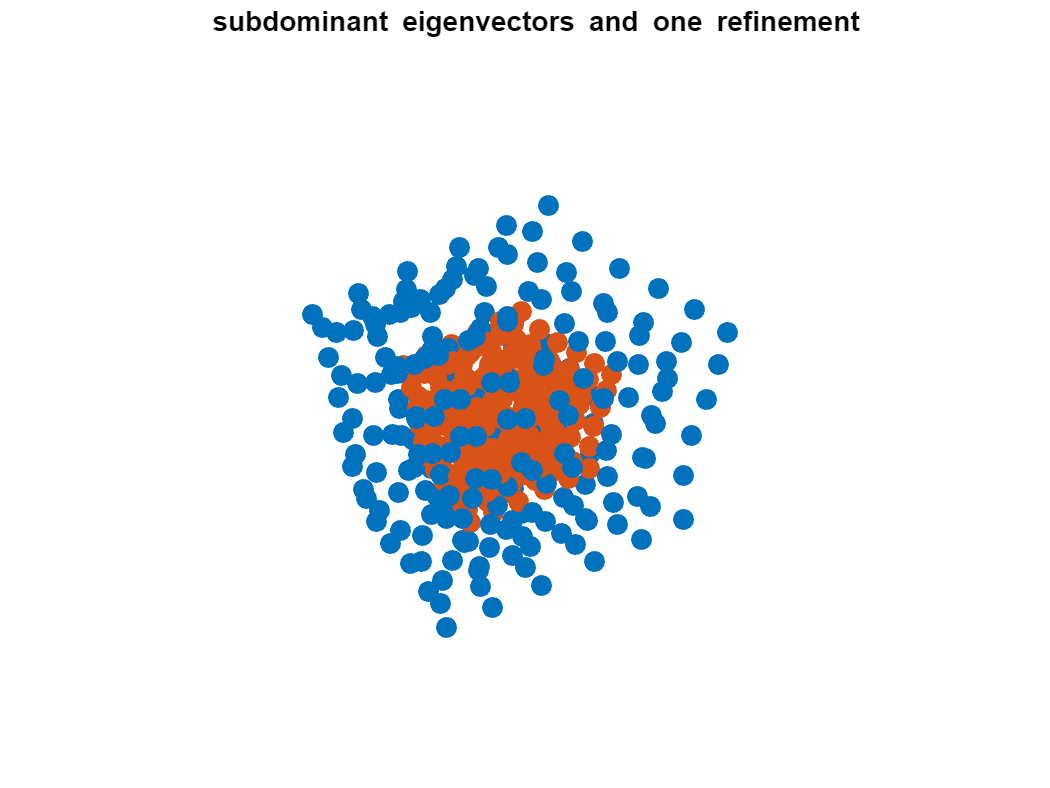

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and one refinement \newline  ')

V=S2Big*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

Once more: 

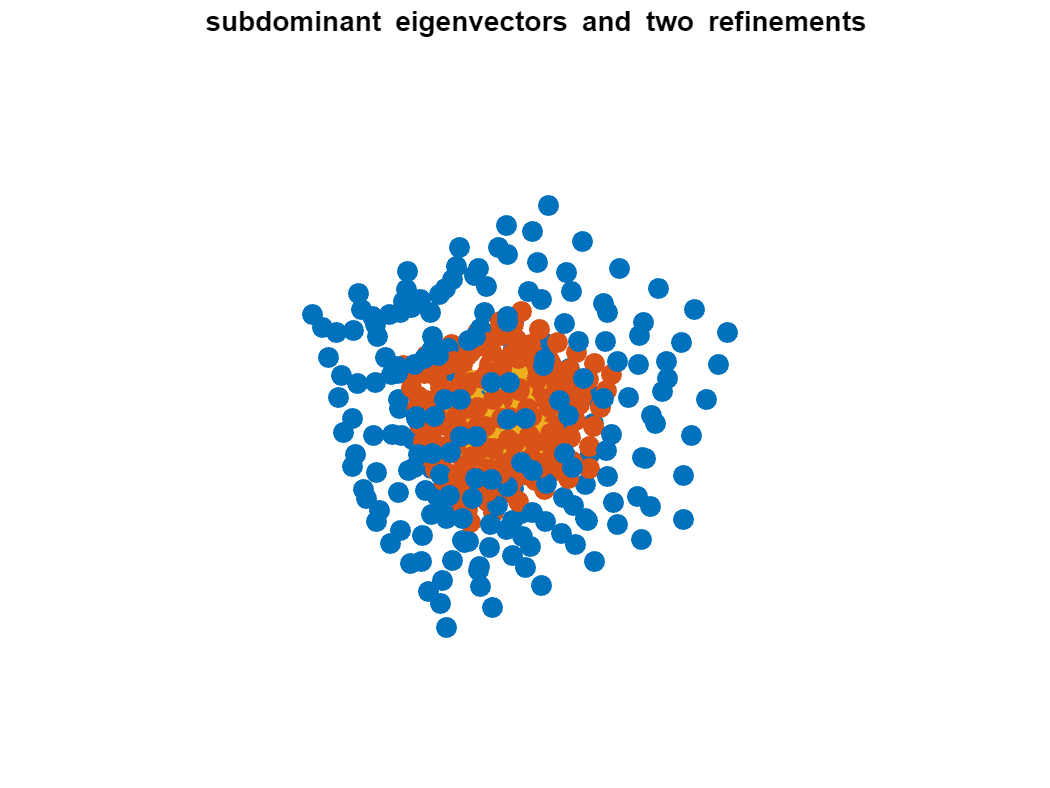

B=S2Big-1/2*eye(length(S2Big));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));

figure
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0 0.4470 0.7410]);
hold on
axis equal
axis off
title('subdominant eigenvectors and two refinements \newline  ')

V=S2Big*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.8500 0.3250 0.0980]);

V=S2Big*V;
plot3(V(:,1),V(:,2),V(:,3),'.','Markersize',25,'Color',[0.9290 0.6940 0.1250]);

### 5.4 Output: Lattice

For the functions with the "Big" suffix, there is an additional output parameter called "Lattice". This parameter encodes the structure of the control points or, more precisely, the underlying structure. Let n represent the number of control points in the structure. Each column of \"Lattice\" then has size n^2, since each column represents an adjacency matrix of a polytope in this structure. The original adjacency matrices can be reconstructed using the command 

[S1Big,Lattice]=computeTriQuadraticSubdivisionMatrixV1Big(F,1/4);
k=length(S1Big);
full(reshape(Lattice(:,1),[k,k]))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

The structure of the "Lattice" matrix for our example is (applies to both variants): 

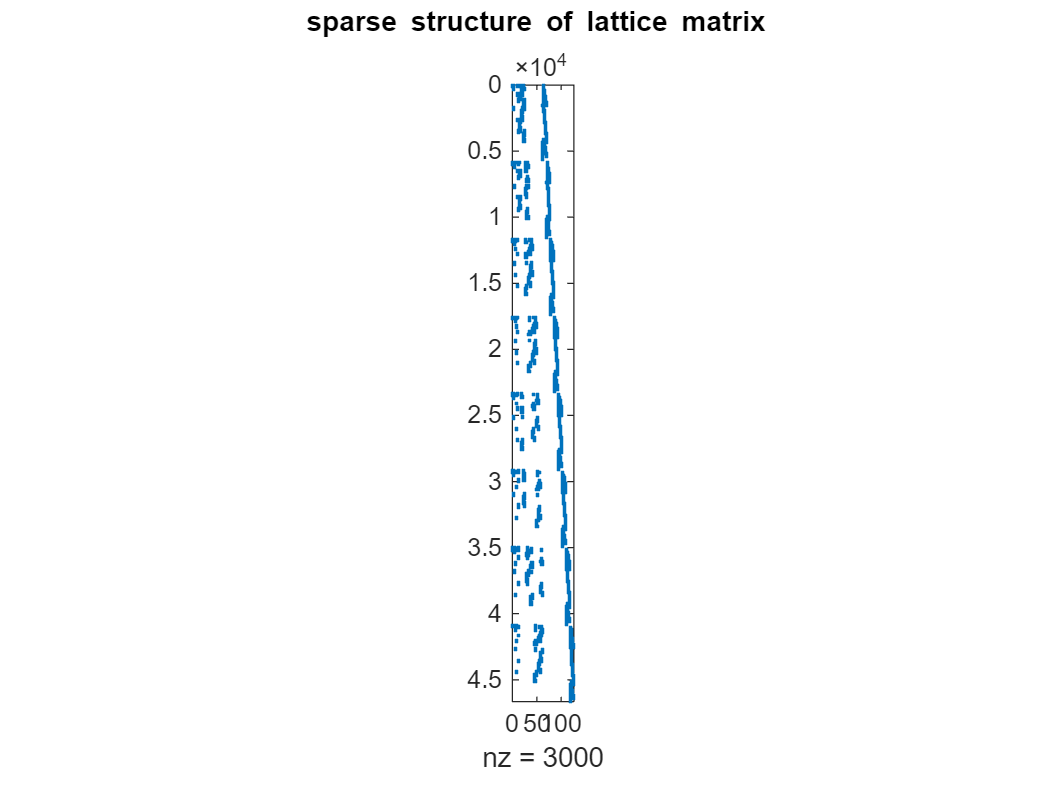

[S2Big,Lattice]=computeTriQuadraticSubdivisionMatrixV2Big(F);

figure
spy(Lattice)
title('sparse structure of lattice matrix \newline ')

### 5.5 Optional Commands

Now we will take a look at the additional input parameters. These parameters are the same for all four variants. Therefore, we will focus on the output for variant 1. 

The first additional input argument is 'Status'. If this parameter is included, the algorithm will display the status of the construction process. Using the following command we get:

%computeTriQuadraticSubdivisionMatrixV1(F,1/4,'Status');

(Remark: Usually the lines are cleared by the clc command. A realistic view of this optional input can be seen in the corresponding demo DemoCubic)

Similarly, for the "Big" function, using the following command we get

%computeTriQuadraticSubdivisionMatrixV1Big(F,1/4,'Status');

(Remark: Usually the lines are cleared by the clc command. A realistic view of this optional input can be seen in the corresponding demo DemoCubic)

The second additional input argument is 'PreventInputCheck'. If this parameter is included, the algorithm will skip the check to ensure that the input represents a planar 3-connected graph. The command is

computeTriQuadraticSubdivisionMatrixV1(F,1/4,'PreventInputCheck');

The third additional input argument is 'Tolerance'. This parameter allows you to manually set the tolerance for the numerical parts of the algorithm. The default value is 10^(-13). The command is 

computeTriQuadraticSubdivisionMatrixV1(F,1/4,'Tolerance',10^(-8));

You can also manually set the maximum number of iterations for the numerical parts using the 'MaxIterations' parameter. The default value is 100. To change it, use the command 

computeTriQuadraticSubdivisionMatrixV1(F,1/4,'MaxIterations',50);

Of course, these options also apply to the functions with the "Big" suffix.

Another input parameter is 'Visualization'. With this parameter, various graphics are generated during the construction process. Use the command 

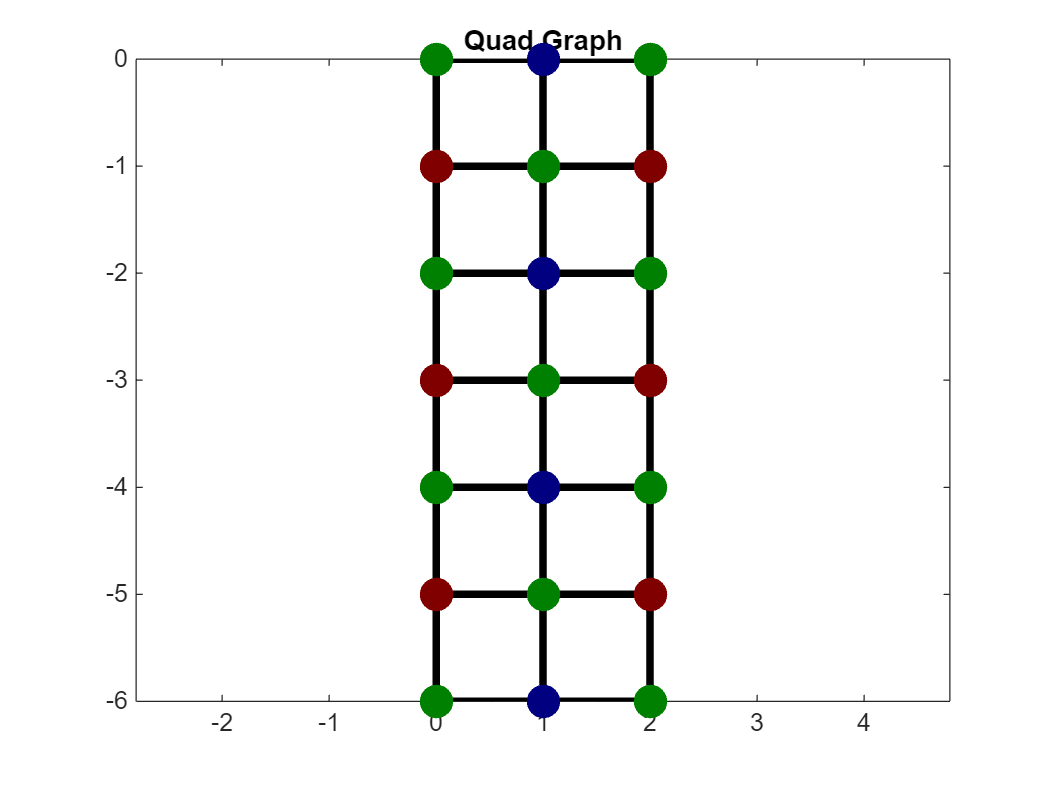

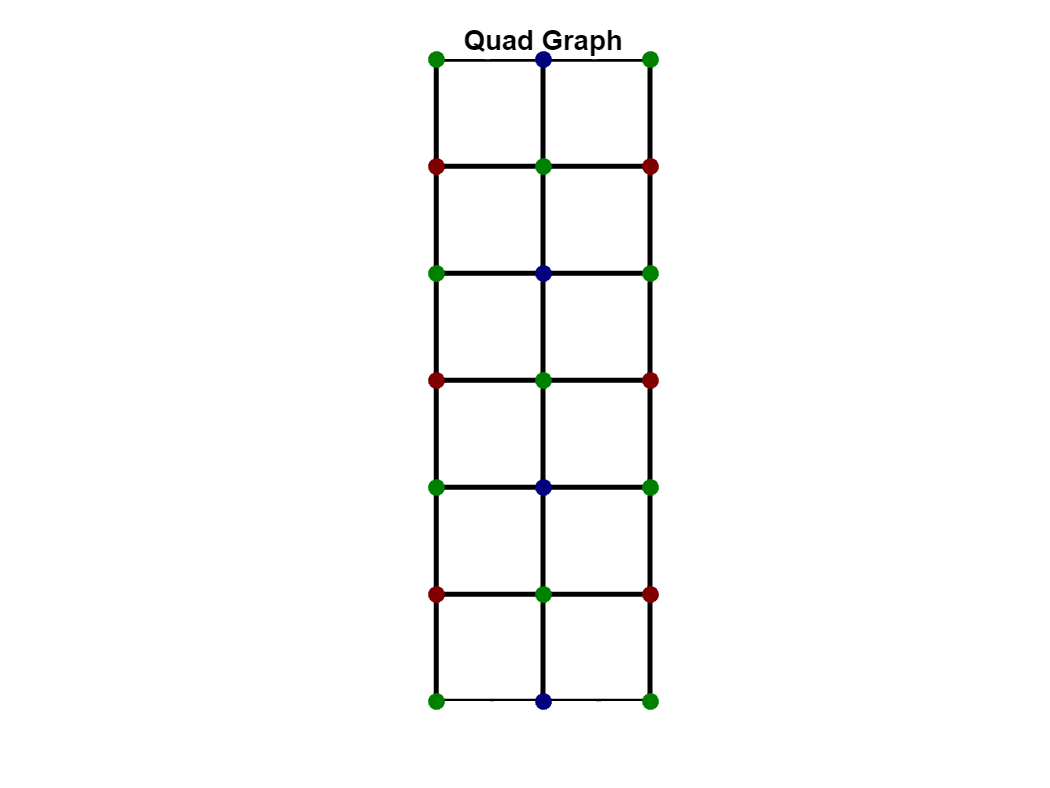

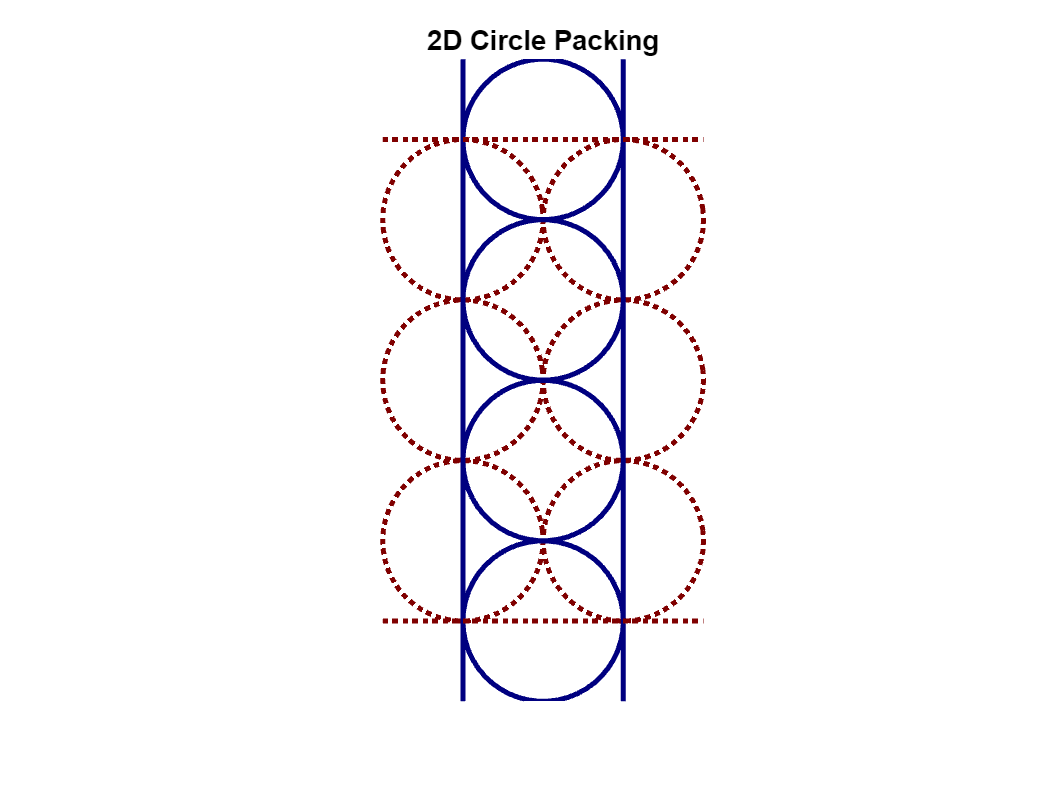

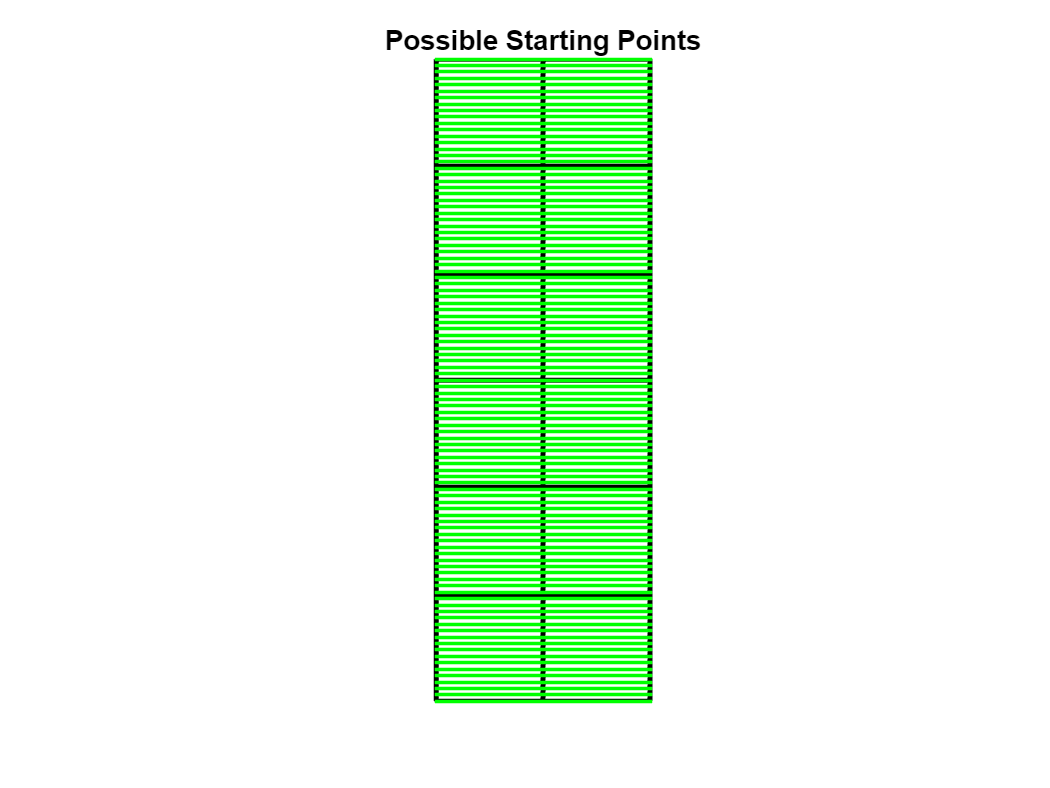

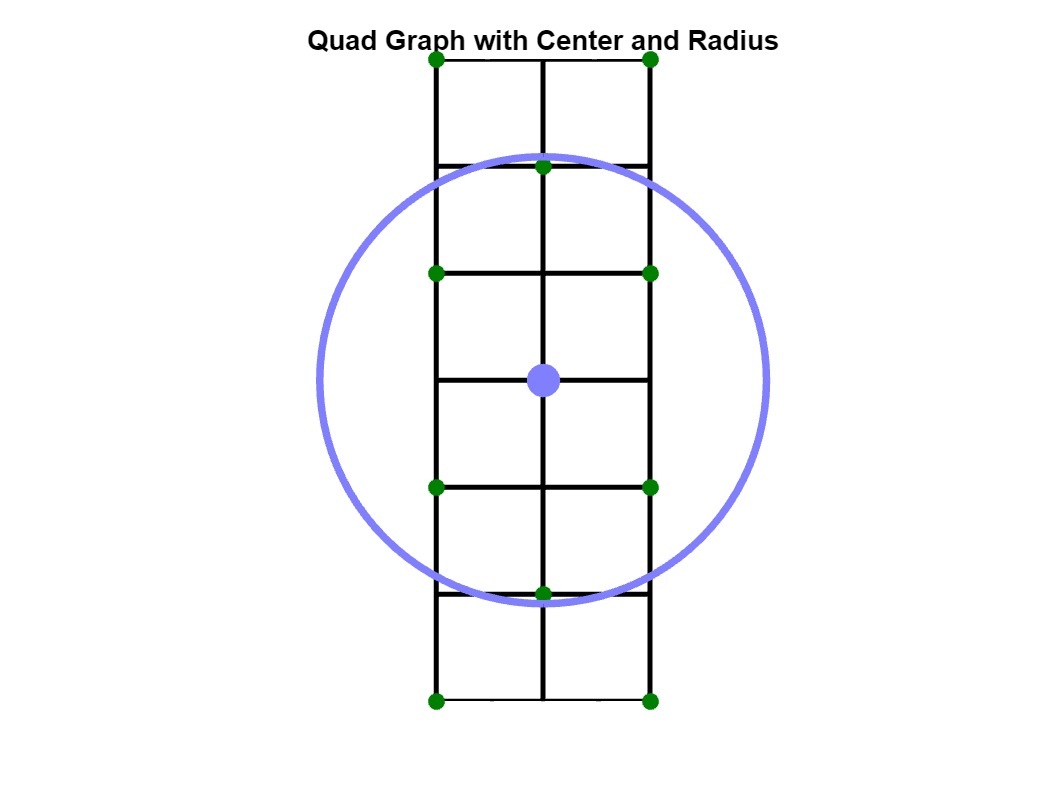

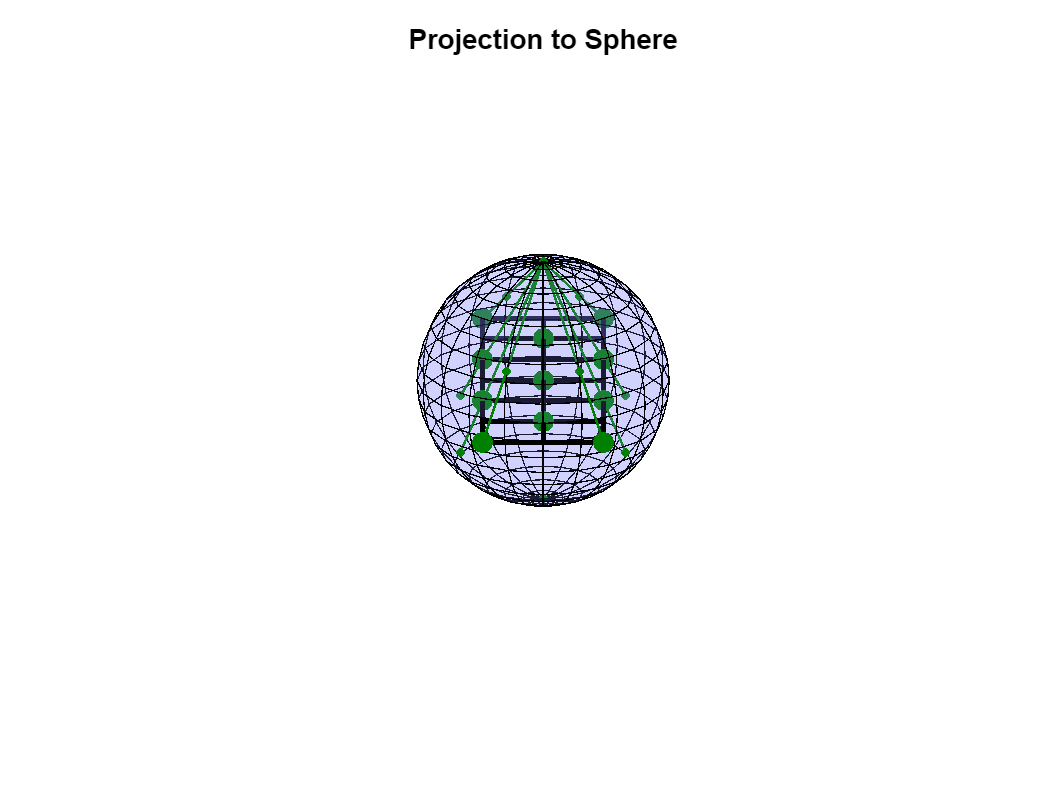

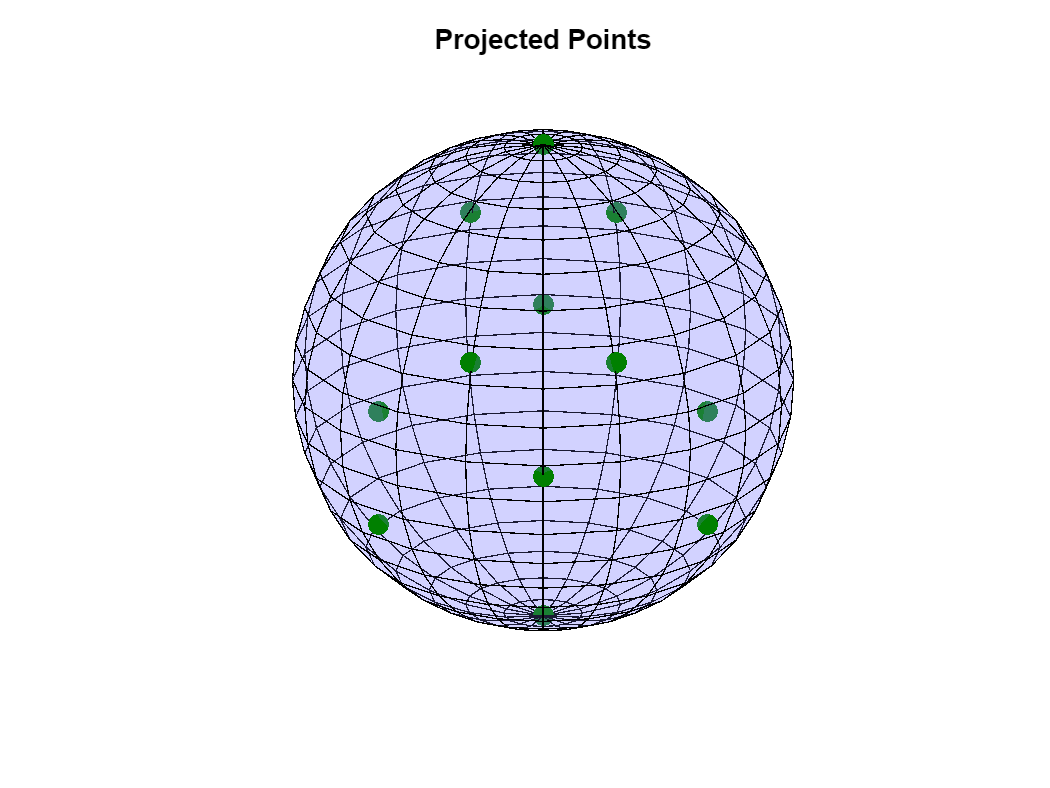

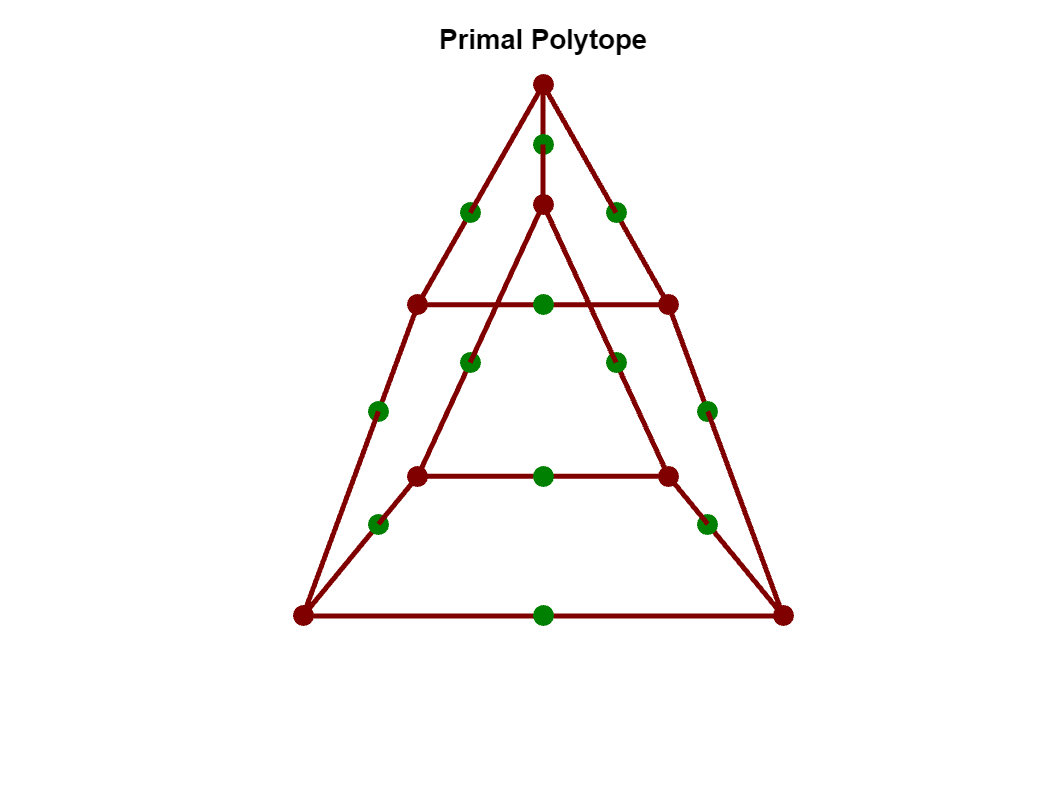

figure
computeTriQuadraticSubdivisionMatrixV1(F,1/4,'Visualization');

A total of 13 figures are created. The background and explanations for these figures can be found in the corresponding dissertation. 

For the functions with the "Big" suffix, only one figure is created. It can be generated with the command

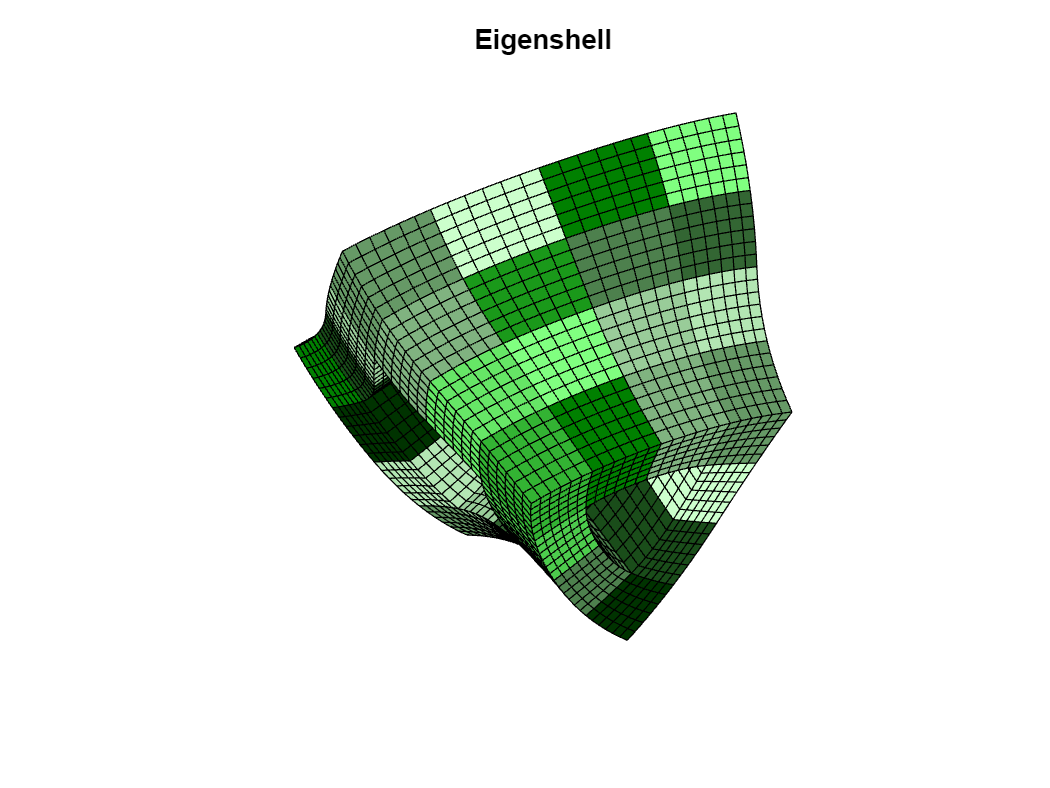

figure
computeTriQuadraticSubdivisionMatrixV1Big(F,1/4,'Visualization');

These figures can be manipulated in different ways. For example, with the command 

%computeTriQuadraticSubdivisionMatrixV1(F,1/4,'Visualization','DrawAfterXKites',4) 

the initial iterative figure will display faster as four kites are drawn in one step.

Using the command 

%computeTriQuadraticSubdivisionMatrixV1(F,1/4,'Visualization','View',[26,5])

the viewing angle of the figures can be adjusted. 

And with the command 

%computeTriQuadraticSubdivisionMatrixV1(F,1/4,'Visualization','PrintImages','Test','.png')

the graphics are exported to .png files with the prefix 'Test' and the suffix '.png'. 

## 6 Quality-of-Life Functions  

There are also two quality-of-life functions.

### 6.1 Plot Function

The first one is a plot function. We start with an example using the following commands

[S,Lattice]=computeTriQuadraticSubdivisionMatrixV1Big(F,1/4);
B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));
Controlpoints=V;

With this, we have a lattice and a set of control points belonging to the eigenshell of the structure. The command

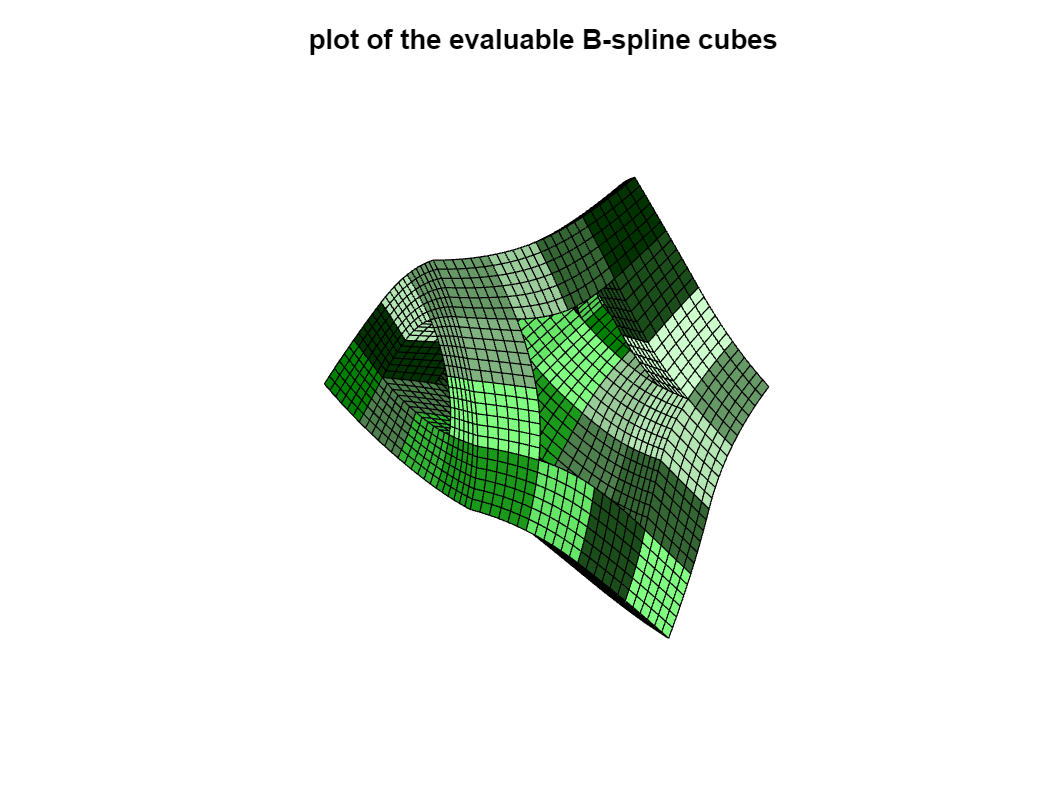

figure
plotTriQuadraticBSplineLattice(Controlpoints,Lattice)
title('plot of the evaluable B-spline cubes')

plots all B-spline cubes that can be evaluated within this structure.

The plot command has two optional input parameters. The first one is 'PointsPerCube'. This parameter allows you to specify how many points each cube should be evaluated in each direction. Using the following command we get:

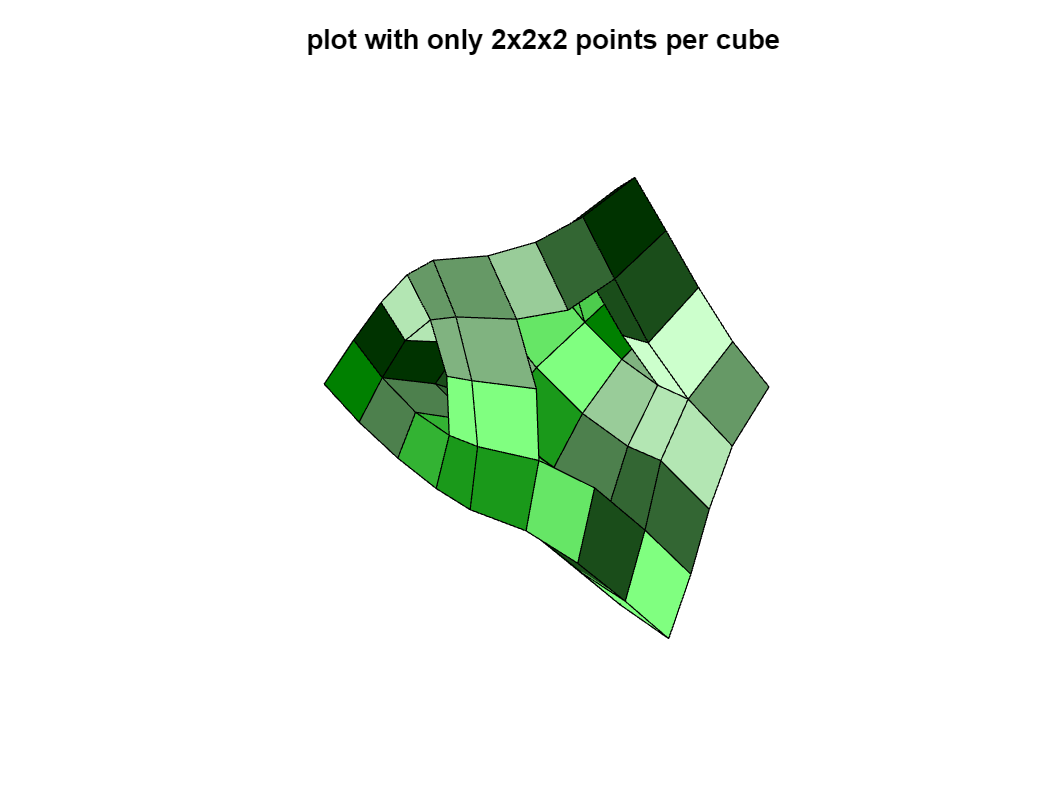

figure
plotTriQuadraticBSplineLattice(Controlpoints,Lattice,'PointsPerCube',2)
title('plot with only 2x2x2 points per cube')

The second optional parameter is 'ColorTable', which allows you to adjust the colors of the cubes. For example, we define:

ColorTable=[0.8,1,0.8;...  %1
            0.7,0.9,0.7;...%2
            0.6,0.8,0.6;...%3
            0.5,0.7,0.5;...%4
            0.4,0.6,0.4;...%5
            0.3,0.5,0.3;...%6
            0.2,0.4,0.2;...&7
            0.1,0.3,0.1;...%8
            0.0,0.2,0.0;...%9
            0,1/2,0;...    %10
            0.5,1,0.5;...  %11
            0.4,0.9,0.4;...%12
            0.3,0.8,0.3;...%13
            0.2,0.7,0.2;...%14
            0.1,0.6,0.1;...%15
            ];

CT=[ColorTable(:,[2,1,3])];

Using the command we get:

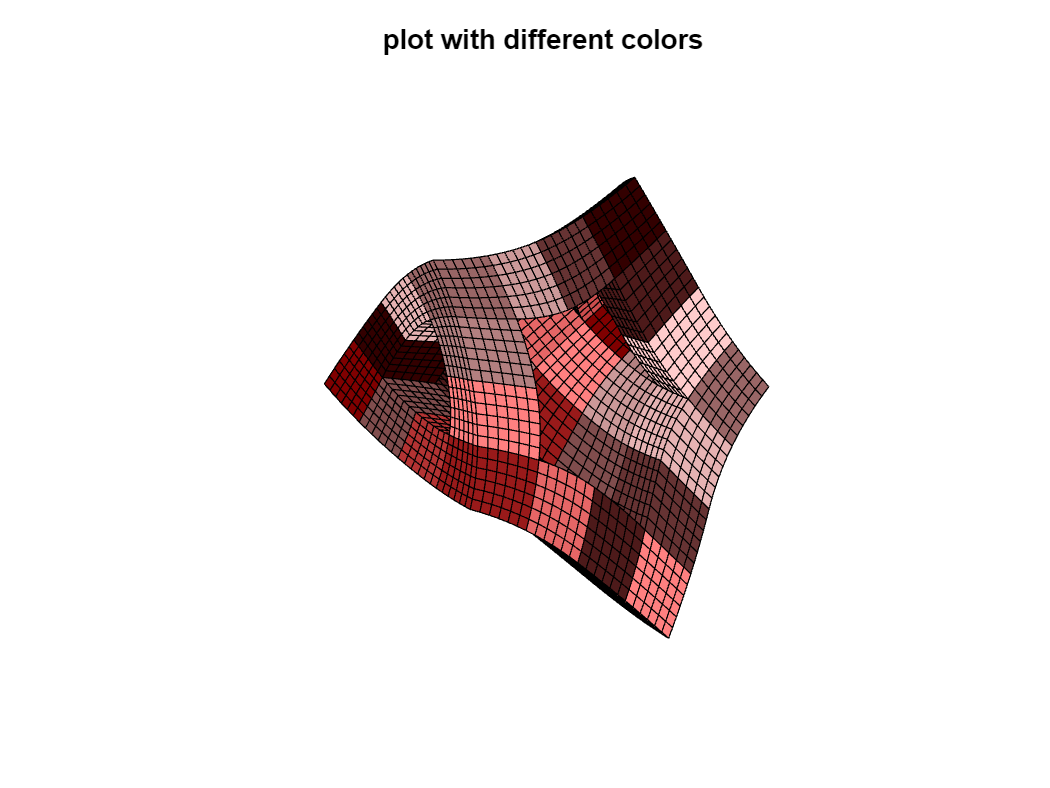

figure
plotTriQuadraticBSplineLattice(Controlpoints,Lattice,'ColorTable',CT)
title('plot with different colors')

### 6.2 Uniform refinement

The second quality-of-life function is  uniform refinement. This function takes a matrix of control points and a lattice matrix and refines the entire structure uniformly. The available functions are: 

RefineTriQuadraticLatticeUniformV1(Controlpoints,Lattice,mu)

RefineTriQuadraticLatticeUniformV2(Controlpoints,Lattice)

The output of these functions is a refined matrix of control points and the updated lattice matrix. Additional output options are available for extracting volumes out of volumes, faces, edges, and points from the lattice (as columns). The functions can also return which vertices are inner vertices and their valences. A simple example is as follows:

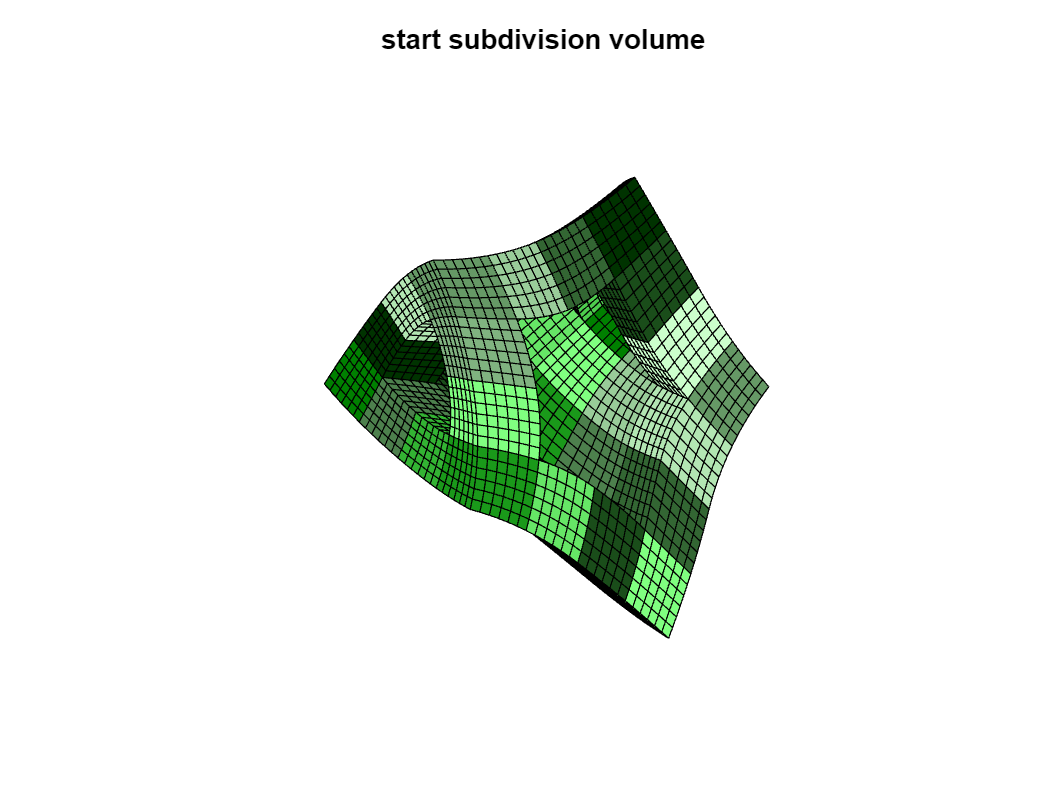

[S,Lattice]=computeTriQuadraticSubdivisionMatrixV1Big(F,1/4);
B=S-1/2*eye(length(S));
B=B'*B;
[V,D]=eig(B);
D=diag(D);
a=abs(D)<10^(-10);
V=V(:,a);
V=real(orth(V));
Controlpoints=V;

figure
plotTriQuadraticBSplineLattice(Controlpoints,Lattice);
title('start subdivision volume')

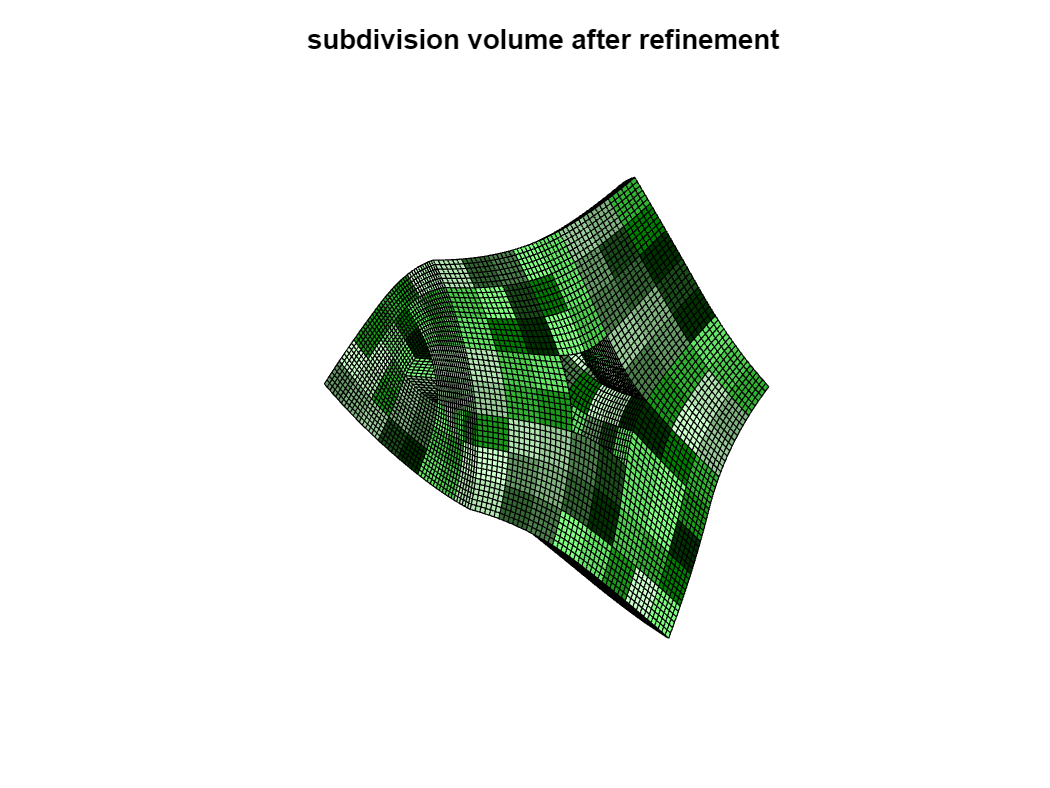

[Controlpoints,Lattice]=RefineTriQuadraticLatticeUniformV1(Controlpoints,Lattice,1/4);
figure
plotTriQuadraticBSplineLattice(Controlpoints,Lattice);
title('subdivision volume after refinement')

This function can also handle lattices containing more than one irregular vertex. Here is an example:

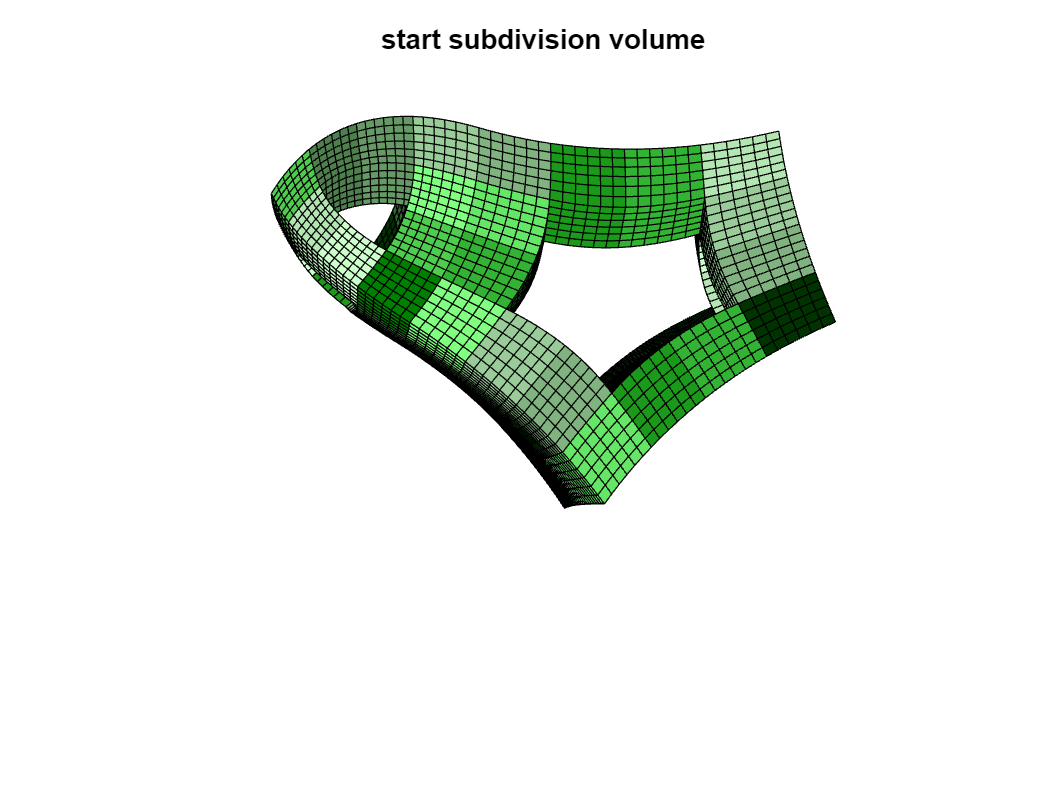

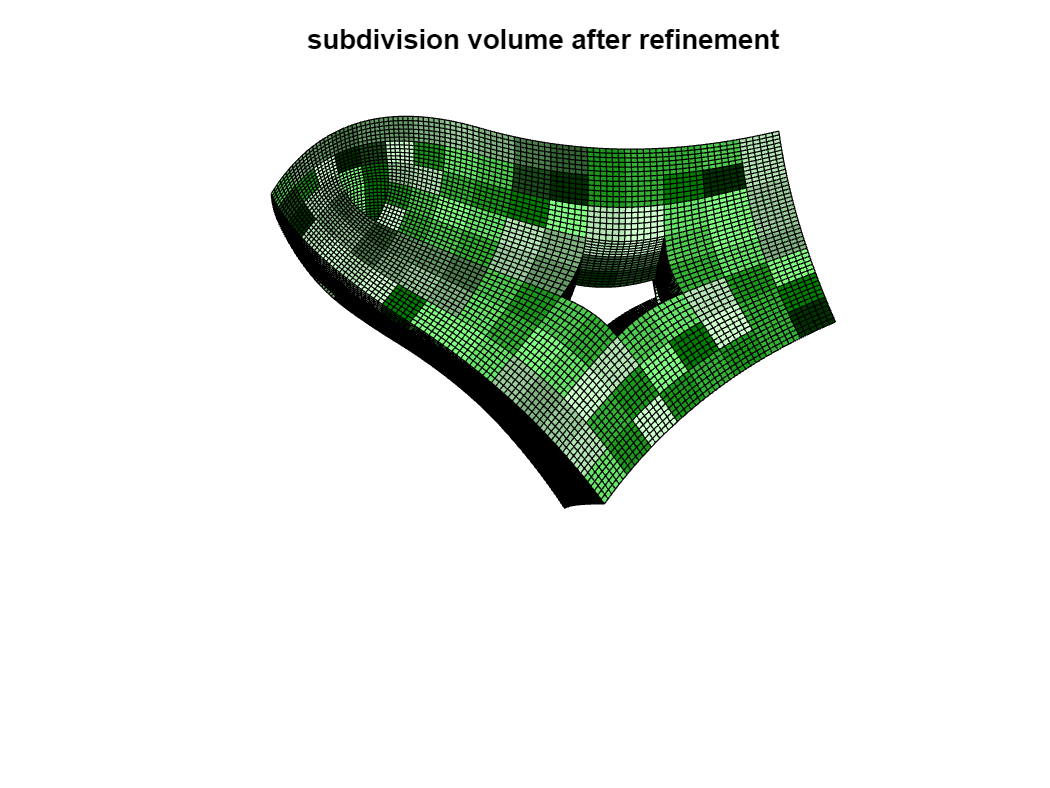

ExampleQuadraticUniformRefinement